# STICS Parameter Selection Guide

Rodrigo Migueles Ramirez, McGill University, April, 2021

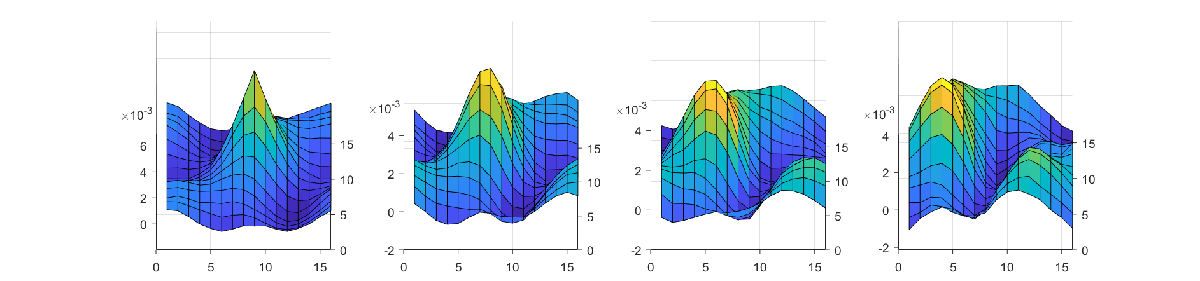

Spatio-Temporal Image Correlation Spectroscopy (STICS) is an image analysis technique based on correlation that allows us to detect intracellular diffusion and flow of fluorescently labeled molecules in live cells. To account for the heterogeneity within the cell, small regions of the image series (*stack*) are analysed sequentially. Furthermore, the stack is also split in the time dimension to account for changes in time of the flow direction or magnitude within the same region. We call the dimensions of these voxels of interest region of interest (ROI) and time of interest (TOI). One of the major difficulties in the use of STICS, and perhaps a serious limitation for its application by non-experts, is the selection of the size of these regions. So far, the selection of these parameters has been based in the visual accordance between the resulting vector maps and the time series data, and no data-based method to measure the appropriatedness of the selected parameters has been developed to my knowledge. Here, I propose a metric to compare parameter combinations and discuss how the selection of these parameters can be guided by the features contained in the data and how they can be tuned to detect or *pick-up* specific spatiotemporal regimes. 

First, let's read a stack (TIFF) file and display the first frames.

[fileID, filePath] = uigetfile(".tif");
stack = readFileToStack([filePath, fileID]);
try
    load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_8x4_5x1_t100r8o8v5.mat');
catch 
    load('C:\Users\Rodrigo Migueles\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_8x4_5x1_t100r8o8v5.mat');
end

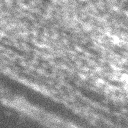

These are 128x128 pixel images of a HUVEC cell stably expressing myosin light chain 9 (MYL9) tagged with mTurquoise. What we see are myosin puncta decorating stress fibers that go across the image from top left to bottom right. Each pixel measures 0.11x0.11 um and the time between frames is 20 seconds with a total of 100 frames. The full-size stack measures 2048x2048 pixels and was acquired using a 60x oil inmersion objective.

In the previous weeks, I have been working on the development of a parallel batch mode for STICS, which allows us to run STICS using either different combinations of parameters, different files, or both. By using this tool, I have analysed this dataset with ROI sizes 8x8, 16x16 and 32x32 pixels and with TOI sizes of 5, 10 and 20 frames. The TOI shift (the displacement of the ROI box) is always set at 4 pixels so that the vector densities are always the same. One thing to keep in mind is that a bigger ROI size will result in a smaller vector field, since the first vector will be placed in the center of the first location of the ROI box. If the box is 32x32 pixels, then the first vector will be placed at (16,16) on the image, whereas if the ROI size is 8x8. then the first vector will be placed at (4,4). In other words, there is always a margin or a region of the image in which no vector will be placed and this margin will increase as the ROI size increases. 

In this example, we will first look at the effect of the ROI size on the measurment of a single vector when using a TOI of 5. We will begin by using an ROI of 8x8, then 16x16 and then 32x32. Once we have compared different ROI sizes using a TOI of 5 we will do the same for TOI sizes of 10 and 20 frames.

To be able to compare across ROI sizes and considering the margins, we will change the vector index as the ROI size changes to show the vector corresponding to the same region in the image. We will work with the first vector of the 32x32 vector field, which would be the 97th vector (4th row, 4th column) in the 8x8 vector field or the 61st (3rd row, 3rd column) in the 16x16 vector field. Keep in mind that the original image is 122x122 pixels. 

(1 + (size(stack,1) - opt.ROIsize)/opt.ROIshift)*(1 + (size(stack,2) - opt.ROIsize)/opt.ROIshift)

ans = 961

Similarly, when we change the TOI size, the number of frames of the vector field changes. To be able to compare the same vector field frame and avoid first-frame artefacts, we will use the second frame of the smallest vector fields, which is the one generated when using a TOI size of 20. The second frame of the TOI = 20 vector field is calculated using the first 20 frames and placed right in the middle of that range. (Technically, this corresponds to the frame 10.5, however, this vector field would be overlayed on top of the 10th frame for visualization purposes). This frame will then correspond to the 7th frame of the TOI=10 vector field and the 9th frame of the TOI = 5 vector field. In general, the $k^{th}$ frame of a n-frames TOI vector field will correspond to the $k+(n-m)/2$ frame of an m-frames TOI vector field. For instance, the 1st frame of a 20-frames TOI vector field corresponds to the 6th ($1+(20-10)/2$) frame of a 10-frames TOI vector field and the 8th frame of a 5-frames TOI vector field.

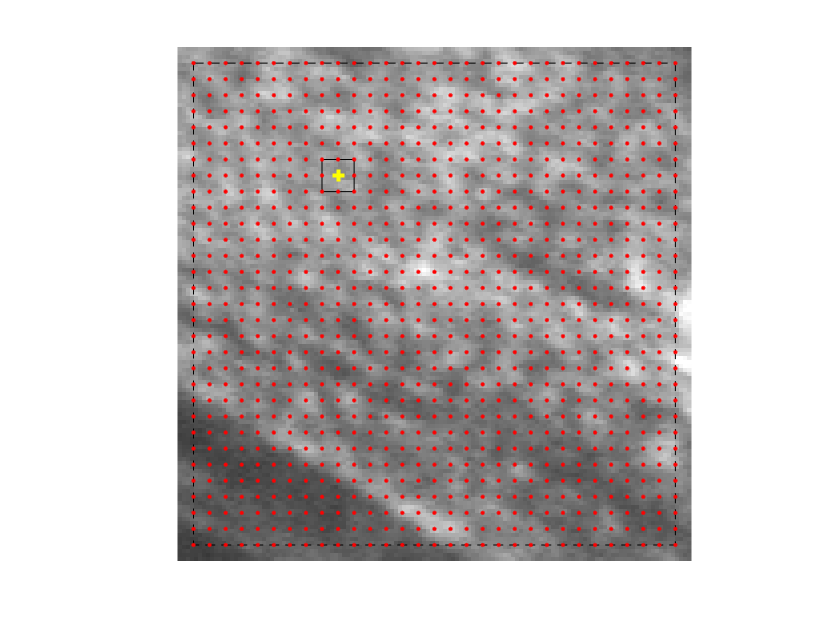

figure;
frame = 34;
vix = 10; 
viy = 8;
px = (vix-1)*opt.ROIshift;
py = (viy-1)*opt.ROIshift;
imshow(stack(:,:,frame), [100,1000], "InitialMagnification","fit"); axis image; hold on
if floor(opt.TOIsize/2)+mod(opt.TOIsize,2) <= frame && frame <= size(stack,3)-opt.TOIsize+1
    rectangle('Position', [(1+opt.ROIsize)/2 (1+opt.ROIsize)/2 size(stack,1)-opt.ROIsize size(stack,1)-opt.ROIsize], 'FaceColor','none', 'LineStyle','--'); hold on
    rectangle('Position', [px+1/2 py+1/2 opt.ROIsize opt.ROIsize]);
    plot(position_x, position_y, '.r');
    plot(px + 1/2 + opt.ROIsize/2, py + 1/2 + opt.ROIsize/2,'+y', 'LineWidth', 2);
end

## ROI size effect

### **ROI = 8x8, TOI = 5**

k = 9; u = 97; % For 8x8 box
try
    load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_8x4_5x1_t100r8o8v5.mat');
catch 
    load('C:\Users\Rodrigo Migueles\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_8x4_5x1_t100r8o8v5.mat');
end
clear timecorr;

Execute STICS calculations for this vector only...

% shift of ROI's amount & define the position of ROI-TOI
fracROIshift = opt.ROIsize/opt.ROIshift;
fracTOIshift = opt.TOIsize/opt.TOIshift;

along_y = floor((size(stack,2)-opt.ROIsize)/opt.ROIshift)+1;
along_x = floor((size(stack,1)-opt.ROIsize)/opt.ROIshift)+1;
along_t = floor((size(stack,3)-opt.TOIsize)/opt.TOIshift)+1;

position_x  =   zeros(1,along_x);
position_y  =   zeros(1,along_y);
position_t  =   zeros(1,along_t);

% defining all of the ROI centers positons in x and y
for i=1:along_x
    position_x(i) = 1/2 + (i-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_x=repmat(position_x,along_y,1);
position_x=position_x';

for j=1:along_y
    position_y(j) = 1/2 + (j-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_y=repmat(position_y,along_x,1);
vectorPositions = ones(along_x,along_y);

[iroi, jroi] = find(vectorPositions);


    position_t(k) = 1/2 + (k-1)/fracTOIshift*opt.TOIsize + opt.TOIsize/2;
    % define whole FOV TOI
    
    TOIFOV = stack(:,:,floor(1+(k-1)/fracTOIshift*opt.TOIsize):floor(opt.TOIsize*(1+((k-1)/fracTOIshift))));
    % define the average FOV TOI image that will be used in the display of the vector maps
    velocityMap{k}.data_TOImean = mean(TOIFOV, 3);
    
    
         i=iroi(u);
         j=jroi(u);
            %define region (x,y,t) on which stics will be applied
            regionanalyse = TOIFOV(floor(1+(i-1)/fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((i-1)/fracROIshift))), floor(1+(j-1)/fracROIshift*opt.ROIsize): floor(opt.ROIsize*(1+((j-1)/fracROIshift))),:);
           
            %apply regular cross-corr stics
            [corrfn] = stics(regionanalyse, opt.tauLimit);
            velocityMap{k}.sigFitRatio(i,j) = size(corrfn,3)/size(regionanalyse,3);    
            

upperTauLimit = min(opt.tauLimit, size(regionanalyse,3));

    fftStack = double(zeros(size(regionanalyse)));
    imageMean = squeeze(mean(mean(regionanalyse,1),2));   
    imageMean(imageMean==0)=10^-12;    
    for frame = 1:size(regionanalyse,3)
        fftStack(:,:,frame) = fft2(double(regionanalyse(:,:,frame)));
    end
  
    for tau = 0:upperTauLimit-1
        lagcorr = zeros(size(regionanalyse,1),size(regionanalyse,2),(size(regionanalyse,3)-tau));
        for pair=1:(size(regionanalyse,3)-tau)
            %lagcorr(:,:,pair) = fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau)));
            lagcorr(:,:,pair) = ifft2(fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau))),'symmetric')./(imageMean(pair)*imageMean(pair+tau));
                
        end
        %timecorr(:,:,(tau+1)) = fftshift(ifft2mod(mean(lagcorr,3),'symmetric'));
        timecorr(:,:,(tau+1)) = fftshift(mean(lagcorr,3))./size(regionanalyse,1)./size(regionanalyse,2)-1;    
    end

Let's take a look at what the stack looks like inside of the 8x8 ROI size during the 5 frames of our TOI:

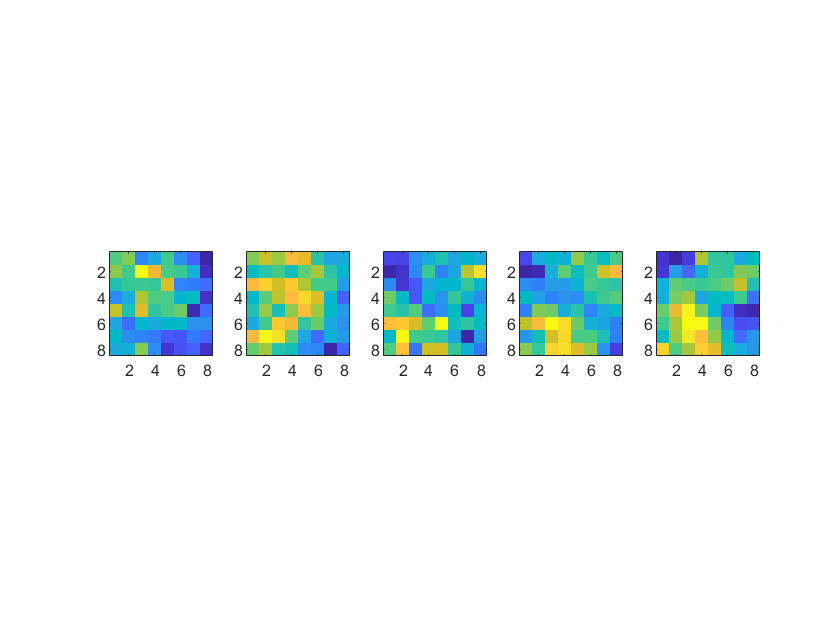

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(regionanalyse(:,:,frame)); axis image;
end

%     sv(regionanalyse);

The STICS code calculates the 2D image correlation function between the first frame and itself (autocorrelation), then between the 1st frame and the 2nd frame (cross-correlation), then between the 1st frame and the 3rd and so on. Here are each of the 5 IC(C)S produced by the STICS code based on this region of interest.

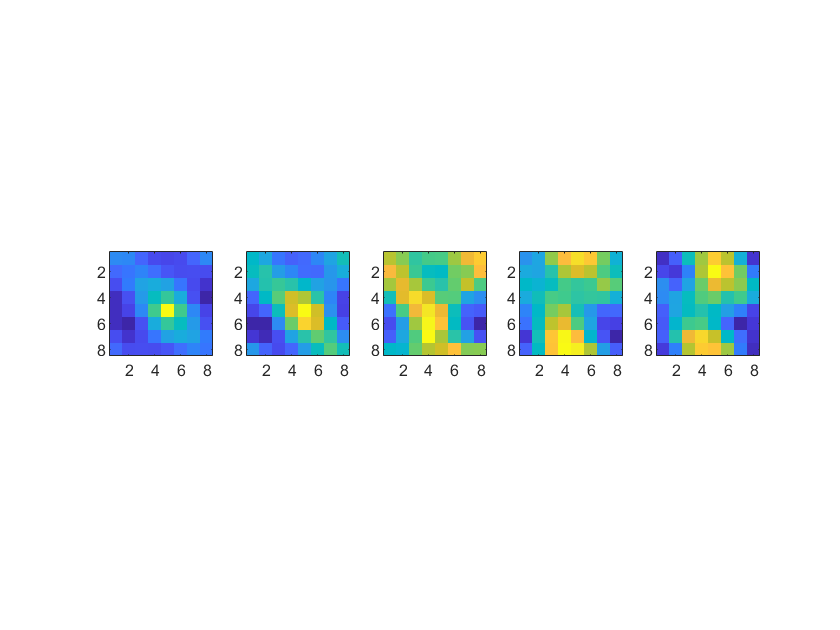

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(timecorr(:,:,frame)); axis image;
end

As you can see, as the time difference (tau) increases, the ICS function looks more and more different from the initial tau step. In theory, one would expect a main peak near the center of the image, with its center somewhat shifted with respect to the center. This displacement of the peak's center is what is used to calculate the flow. However, if the ROI size and TOI size are not chosen properly, the ICS functions that we obtain look far from a major peak shifting in time. To determine the significance of an ICS peak, we can use a criteria defined by Ji et al. (Ji et al. 2005, J. of Microscopy). By using this criteria we can determine which of these ICS functions are significant and which are not. Let's see which of these ICS functions are significant:

figure
for frame = 1:size(corrfn,3)
    subplot(1,size(corrfn,3),frame);
    imagesc(corrfn(:,:,frame)); axis image; hold on
%     plot(velocityMap{k}.coeffGtime{i,j}(frame,5)+(opt.ROIsize/2)+1, velocityMap{k}.coeffGtime{i,j}(frame,6)+(opt.ROIsize/2)+1, "+r","LineWidth",1.5);
end

This is the cornerstone of the proposed metric for parameter appropriatedness: the number of ICS functions deemed significant over the total number of ICS functions available. Once the significant ICS functions have been identified, each of them is fitted with a Gaussian function to measure its features and the coordenates in x and y of the peak of the fitted Gaussian are used to fit a least-squares model of a straight line going from one point to the next. The magnitude and orientation of the velocity vector are determined from this linear fit to the coordinates of the center of the peaks. In that sense, the underlying assumption is that the more points are given to the linear model, the more acurate will be the estimate of the velocity. In this way, errors in the Gaussian fit, thus in the determination of the center of the peak), will be counter balanced by the rest of the points that will be used to determine the vector velocity. 

In this case, the significance ratio would be 

disp([num2str(size(corrfn,3)/size(timecorr,3)*100), '%']);

100%


Now let's take a look at what the coordinates of the centers of the fitted Gaussians are for these two correlation functions:

velocityMap{k}.coeffGtime{i,j}

ans =     0.0033    0.1601    0.1601   -0.0003    0.0550    0.0551
    0.0019    0.1875    0.1875   -0.0003    0.0457    0.0696


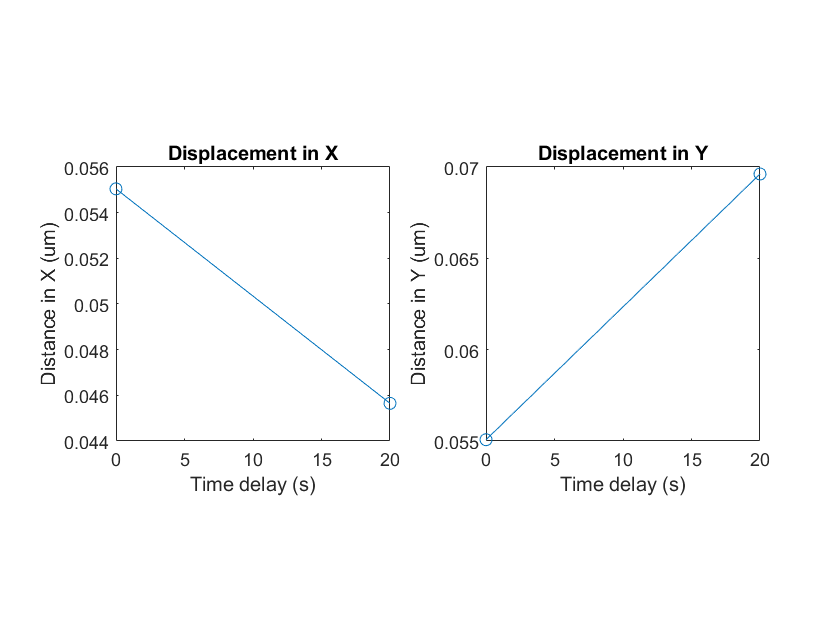

figure;
subplot(1,2,1);
plot(0:opt.timeFrame:opt.timeFrame*size(velocityMap{k}.coeffGtime{i,j},1)-1,...
    velocityMap{k}.coeffGtime{i,j}(:,5), "o-"); title('Displacement in X'); 
xlabel('Time delay (s)'); ylabel('Distance in X (um)'); axis square
subplot(1,2,2);
plot(0:opt.timeFrame:opt.timeFrame*size(velocityMap{k}.coeffGtime{i,j},1)-1,...
    velocityMap{k}.coeffGtime{i,j}(:,6), "o-"); title('Displacement in Y'); 
xlabel('Time delay (s)'); ylabel('Distance in Y (um)'); axis square

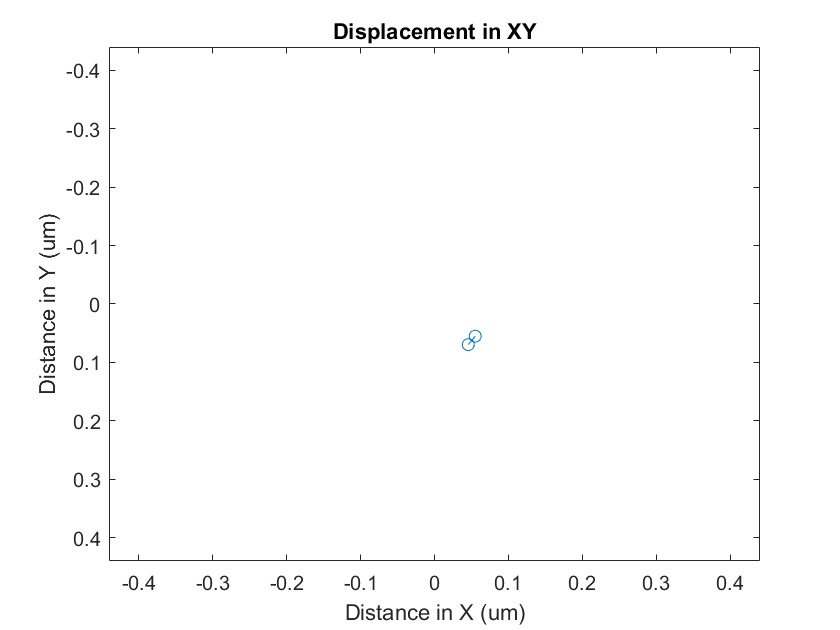

figure;
plot(velocityMap{k}.coeffGtime{i,j}(:,5), velocityMap{k}.coeffGtime{i,j}(:,6), "o-");
title('Displacement in XY'); 
xlabel('Distance in X (um)'); ylabel('Distance in Y (um)');
xlim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]); ylim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]);
axis ij

Keep in mind that in MATLAB, the axis are such that the values increase in space towards the bottom-right corner of the quardant, so an increase in both coordinates is seen as a movement of the center of the Gaussian toward the bottom right in the correlation functions, whereas it represents an effective flow in the opposite direction in ImageJ-based axis images.

### ROI = 16x16, TOI = 5

Let's see what does using a ROI size of 16x16 looks like. 

Load the appropriate velocity map, change the vector index to `u = 61` and run STICS:

u = 61; clear timecorr;
try
    load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_16x4_5x1_t100r16o16v5.mat');
catch 
    load('C:\Users\Rodrigo Migueles\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_16x4_5x1_t100r16o16v5.mat');
end

Execute STICS calculations for this vector only...

% shift of ROI's amount & define the position of ROI-TOI
fracROIshift = opt.ROIsize/opt.ROIshift;
fracTOIshift = opt.TOIsize/opt.TOIshift;

along_y = floor((size(stack,2)-opt.ROIsize)/opt.ROIshift)+1;
along_x = floor((size(stack,1)-opt.ROIsize)/opt.ROIshift)+1;
along_t = floor((size(stack,3)-opt.TOIsize)/opt.TOIshift)+1;

position_x  =   zeros(1,along_x);
position_y  =   zeros(1,along_y);
position_t  =   zeros(1,along_t);

% defining all of the ROI centers positons in x and y
for i=1:along_x
    position_x(i) = 1/2 + (i-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_x=repmat(position_x,along_y,1);
position_x=position_x';

for j=1:along_y
    position_y(j) = 1/2 + (j-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_y=repmat(position_y,along_x,1);
vectorPositions = ones(along_x,along_y);

[iroi, jroi] = find(vectorPositions);


    position_t(k) = 1/2 + (k-1)/fracTOIshift*opt.TOIsize + opt.TOIsize/2;
    % define whole FOV TOI
    
    TOIFOV = stack(:,:,floor(1+(k-1)/fracTOIshift*opt.TOIsize):floor(opt.TOIsize*(1+((k-1)/fracTOIshift))));
    % define the average FOV TOI image that will be used in the display of the vector maps
    velocityMap{k}.data_TOImean = mean(TOIFOV, 3);
    
    
         i=iroi(u);
         j=jroi(u);
            %define region (x,y,t) on which stics will be applied
            regionanalyse = TOIFOV(floor(1+(i-1)/fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((i-1)/fracROIshift))), floor(1+(j-1)/fracROIshift*opt.ROIsize): floor(opt.ROIsize*(1+((j-1)/fracROIshift))),:);
           
            %apply regular cross-corr stics
            [corrfn] = stics(regionanalyse, opt.tauLimit);
            velocityMap{k}.sigFitRatio(i,j) = size(corrfn,3)/size(regionanalyse,3);    
            

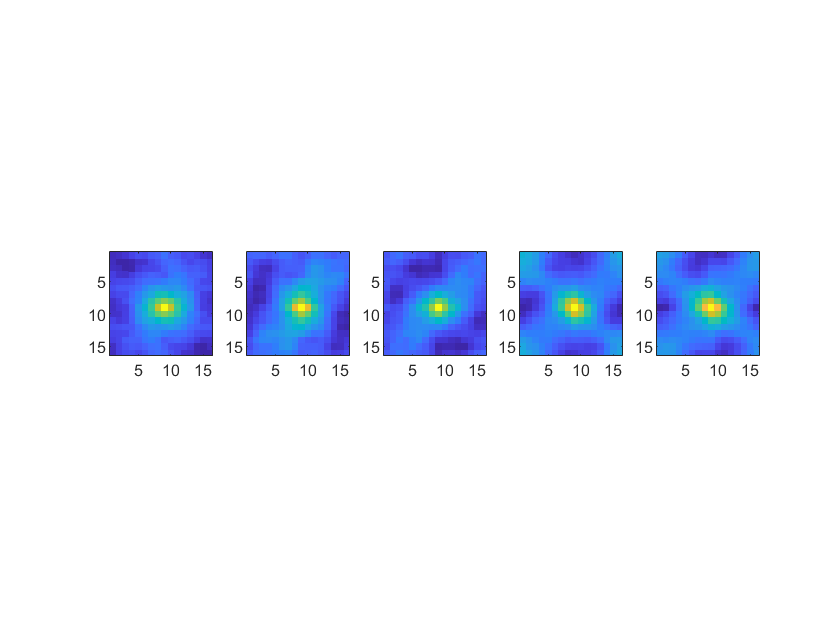

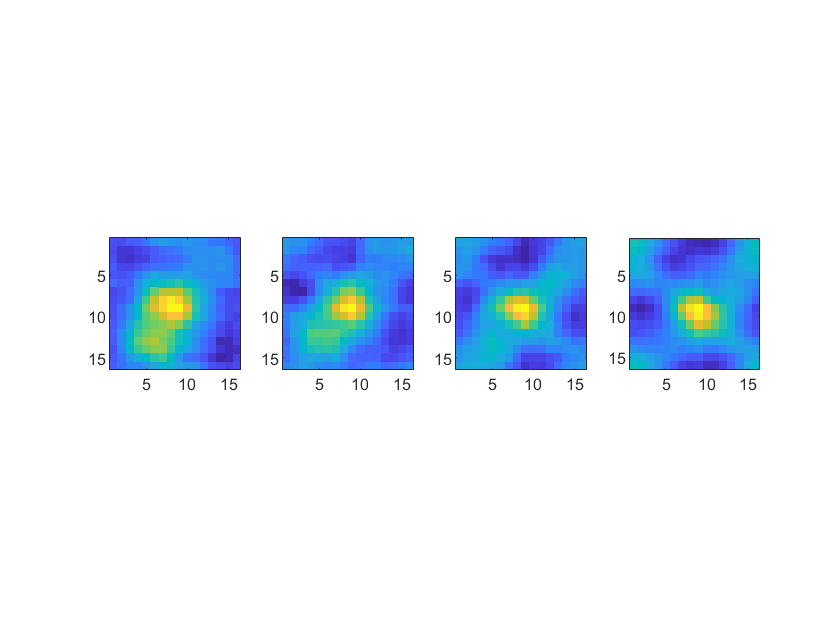

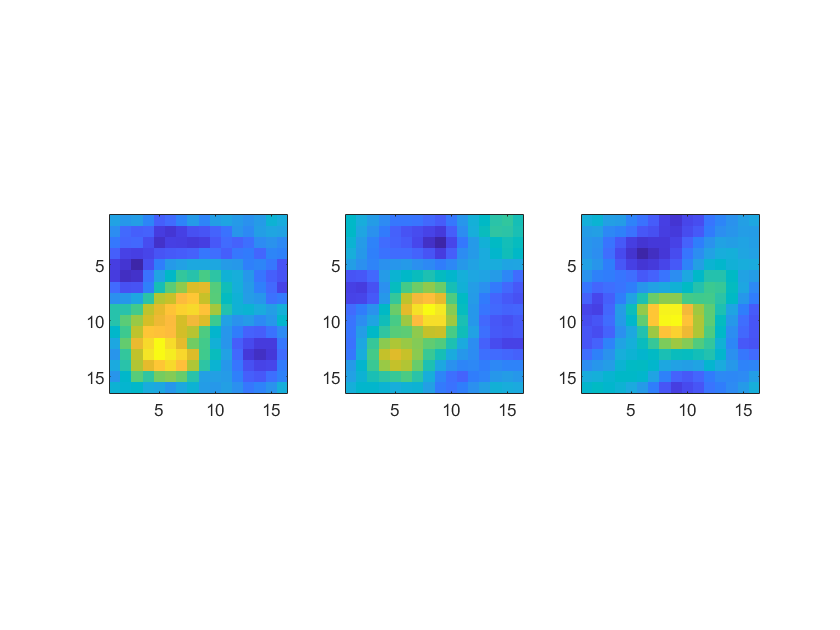

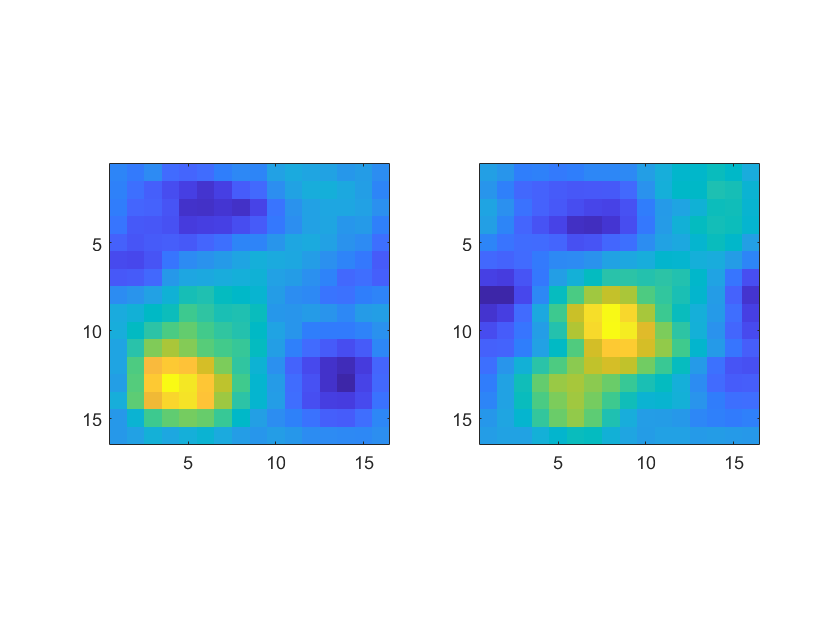

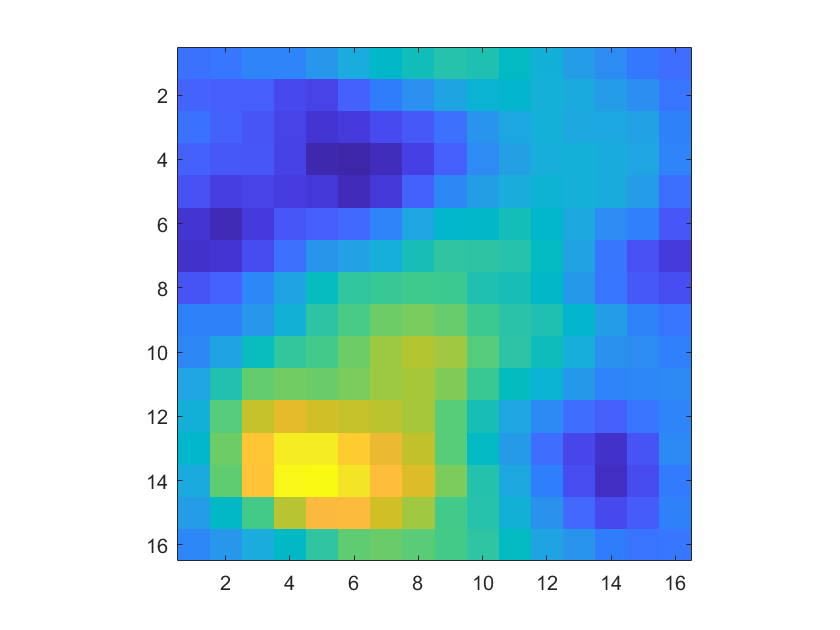

upperTauLimit = min(opt.tauLimit, size(regionanalyse,3));

    fftStack = double(zeros(size(regionanalyse)));
    imageMean = squeeze(mean(mean(regionanalyse,1),2));   
    imageMean(imageMean==0)=10^-12;    
    for frame = 1:size(regionanalyse,3)
        fftStack(:,:,frame) = fft2(double(regionanalyse(:,:,frame)));
    end
  
    for tau = 0:upperTauLimit-1
        lagcorr = zeros(size(regionanalyse,1),size(regionanalyse,2),(size(regionanalyse,3)-tau));
        for pair=1:(size(regionanalyse,3)-tau)
            %lagcorr(:,:,pair) = fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau)));
            lagcorr(:,:,pair) = ifft2(fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau))),'symmetric')./(imageMean(pair)*imageMean(pair+tau));
                
        end
        %timecorr(:,:,(tau+1)) = fftshift(ifft2mod(mean(lagcorr,3),'symmetric'));
        timecorr(:,:,(tau+1)) = fftshift(mean(lagcorr,3))./size(regionanalyse,1)./size(regionanalyse,2)-1;    
        
        figure
        for frame = 1:size(lagcorr, 3)
            subplot(1,size(lagcorr, 3),frame);
            imagesc(fftshift(lagcorr(:,:,frame))); axis image;
        end
    end

Let's take a look at what the stack looks like inside of the 16x16 ROI size during the 5 frames of our TOI:

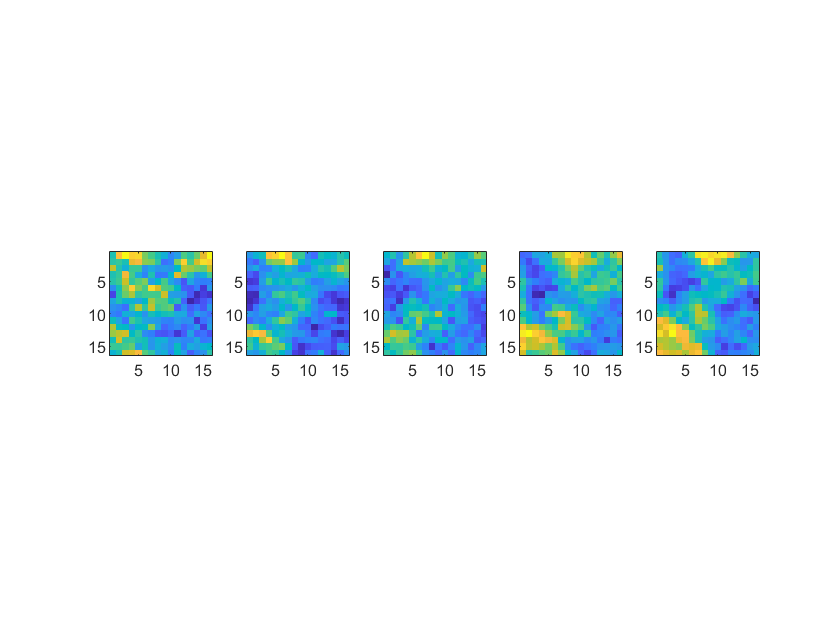

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(regionanalyse(:,:,frame)); axis image;
end

Here are each of the 5 IC(C)S produced by the STICS code based on this region of interest.

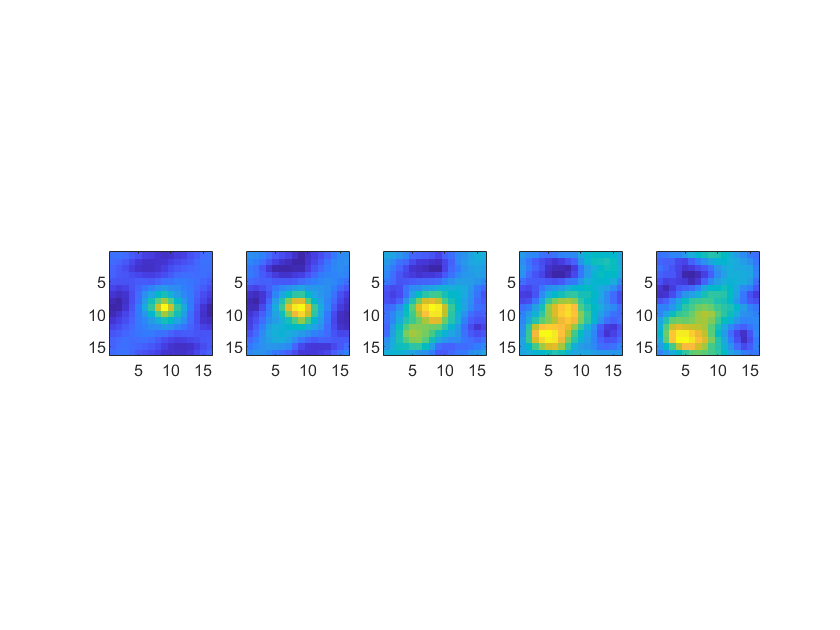

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(timecorr(:,:,frame)); axis image;
end

Let's see which of these ICS functions are significant:

figure
for frame = 1:size(corrfn,3)
    subplot(1,size(corrfn,3),frame);
    imagesc(corrfn(:,:,frame)); axis image; hold on
%     plot(velocityMap{k}.coeffGtime{i,j}(frame,5)+(opt.ROIsize/2)+1, velocityMap{k}.coeffGtime{i,j}(frame,6)+(opt.ROIsize/2)+1, "+r","LineWidth",1.5);
end

Our significance ratio is then 

disp([num2str(size(corrfn,3)/size(timecorr,3)*100), '%']);

100%


velocityMap{k}.coeffGtime{i,j}

ans =     0.0048    0.3168    0.3168   -0.0005    0.0551    0.0550
    0.0040    0.3417    0.3417   -0.0005    0.0028    0.0999
    0.0031    0.4154    0.4154   -0.0005   -0.0905    0.1979
    0.0027    0.4637    0.4637   -0.0005   -0.2126    0.3630


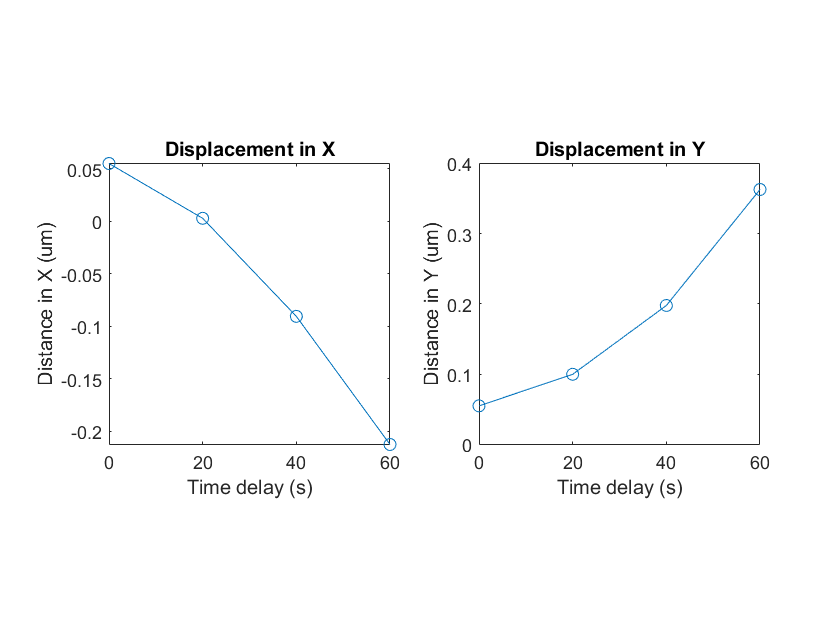


figure;
subplot(1,2,1);
plot(0:opt.timeFrame:opt.timeFrame*size(velocityMap{k}.coeffGtime{i,j},1)-1,...
    velocityMap{k}.coeffGtime{i,j}(:,5), "o-"); title('Displacement in X'); 
xlabel('Time delay (s)'); ylabel('Distance in X (um)'); axis square
subplot(1,2,2);
plot(0:opt.timeFrame:opt.timeFrame*size(velocityMap{k}.coeffGtime{i,j},1)-1,...
    velocityMap{k}.coeffGtime{i,j}(:,6), "o-"); title('Displacement in Y'); 
xlabel('Time delay (s)'); ylabel('Distance in Y (um)'); axis square

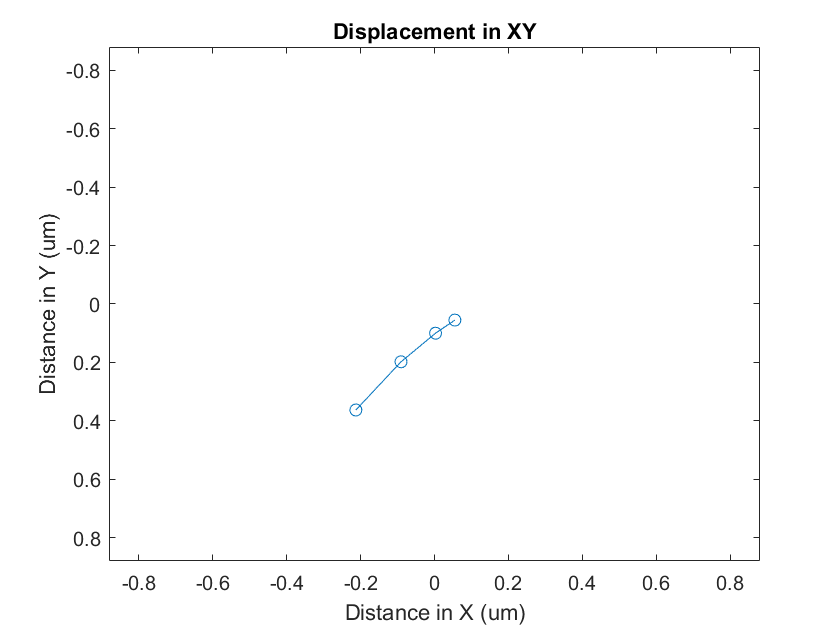

figure;
plot(velocityMap{k}.coeffGtime{i,j}(:,5), velocityMap{k}.coeffGtime{i,j}(:,6), "o-");
title('Displacement in XY'); 
xlabel('Distance in X (um)'); ylabel('Distance in Y (um)');
xlim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]); 
ylim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]);
axis ij

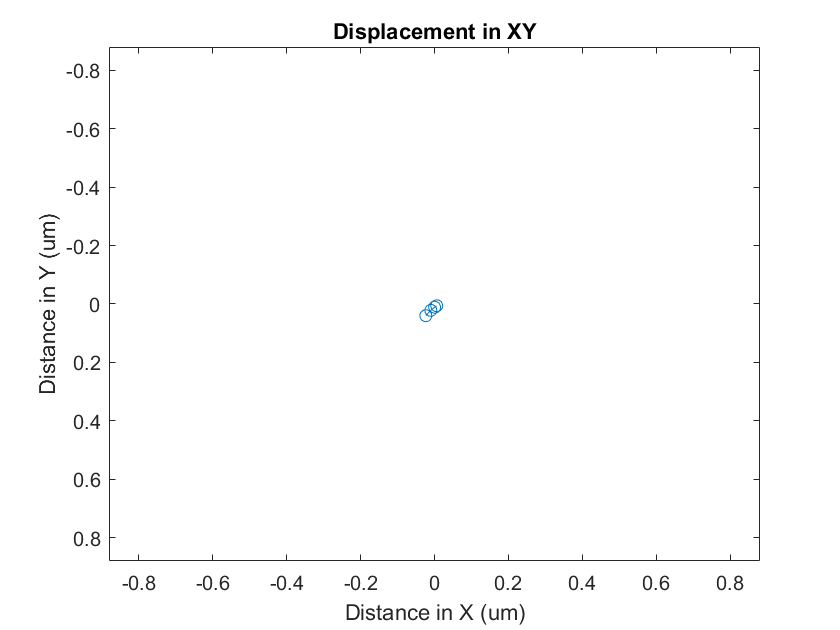

figure;
plot(opt.pixelSize*velocityMap{k}.coeffGtime{i,j}(:,5), opt.pixelSize*velocityMap{k}.coeffGtime{i,j}(:,6), "o-");
title('Displacement in XY'); 
xlabel('Distance in X (um)'); ylabel('Distance in Y (um)');
xlim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]); 
ylim([-opt.pixelSize*opt.ROIsize/2, opt.pixelSize*opt.ROIsize/2]);
axis ij

### ROI = 32x32, TOI = 5

Following the same logic, here are the results for a ROI of 32x32 pixels:

u = 1; clear timecorr;
try
    load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_32x4_5x1_t100r32o32v5.mat');
catch
    load('C:\Users\Rodrigo Migueles\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_32x4_5x1_t100r32o32v5.mat');
end

% shift of ROI's amount & define the position of ROI-TOI
fracROIshift = opt.ROIsize/opt.ROIshift;
fracTOIshift = opt.TOIsize/opt.TOIshift;

along_y = floor((size(stack,2)-opt.ROIsize)/opt.ROIshift)+1;
along_x = floor((size(stack,1)-opt.ROIsize)/opt.ROIshift)+1;
along_t = floor((size(stack,3)-opt.TOIsize)/opt.TOIshift)+1;

position_x  =   zeros(1,along_x);
position_y  =   zeros(1,along_y);
position_t  =   zeros(1,along_t);

% defining all of the ROI centers positons in x and y
for i=1:along_x
    position_x(i) = 1/2 + (i-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_x=repmat(position_x,along_y,1);
position_x=position_x';

for j=1:along_y
    position_y(j) = 1/2 + (j-1)/fracROIshift*opt.ROIsize + opt.ROIsize/2;
end
position_y=repmat(position_y,along_x,1);
vectorPositions = ones(along_x,along_y);

[iroi, jroi] = find(vectorPositions);


    position_t(k) = 1/2 + (k-1)/fracTOIshift*opt.TOIsize + opt.TOIsize/2;
    % define whole FOV TOI
    
    TOIFOV = stack(:,:,floor(1+(k-1)/fracTOIshift*opt.TOIsize):floor(opt.TOIsize*(1+((k-1)/fracTOIshift))));
    % define the average FOV TOI image that will be used in the display of the vector maps
    velocityMap{k}.data_TOImean = mean(TOIFOV, 3);
    
    
         i=iroi(u);
         j=jroi(u);
            %define region (x,y,t) on which stics will be applied
            regionanalyse = TOIFOV(floor(1+(i-1)/fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((i-1)/fracROIshift))), floor(1+(j-1)/fracROIshift*opt.ROIsize): floor(opt.ROIsize*(1+((j-1)/fracROIshift))),:);
           
            %apply regular cross-corr stics
            [corrfn] = stics(regionanalyse, opt.tauLimit);
            velocityMap{k}.sigFitRatio(i,j) = size(corrfn,3)/size(regionanalyse,3);    
            

ans = 1

ans = 1

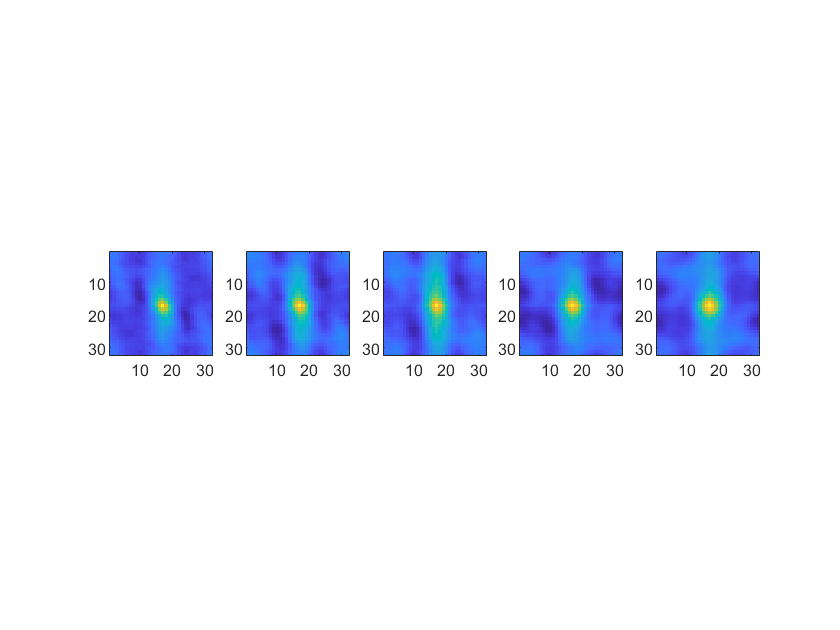

ans = 2

ans = 2

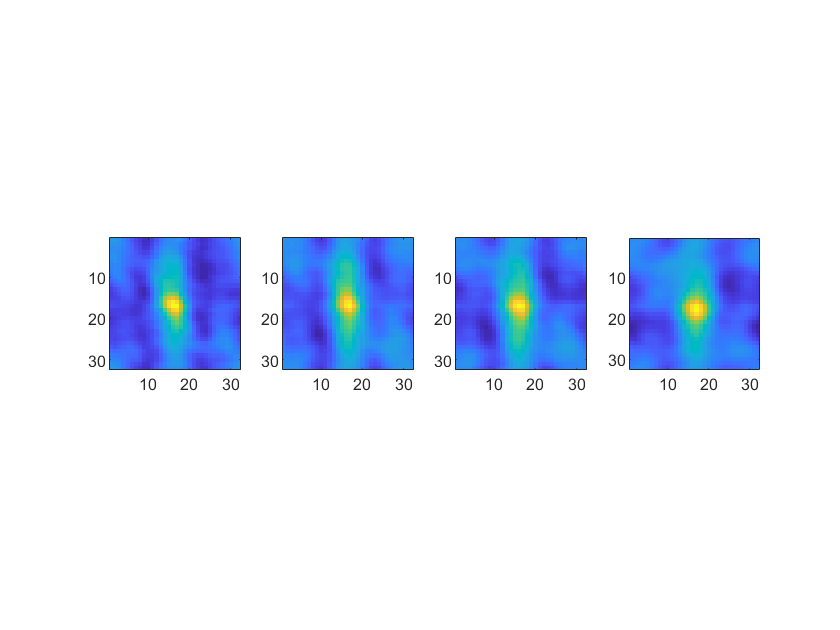

ans = 3

ans = 3

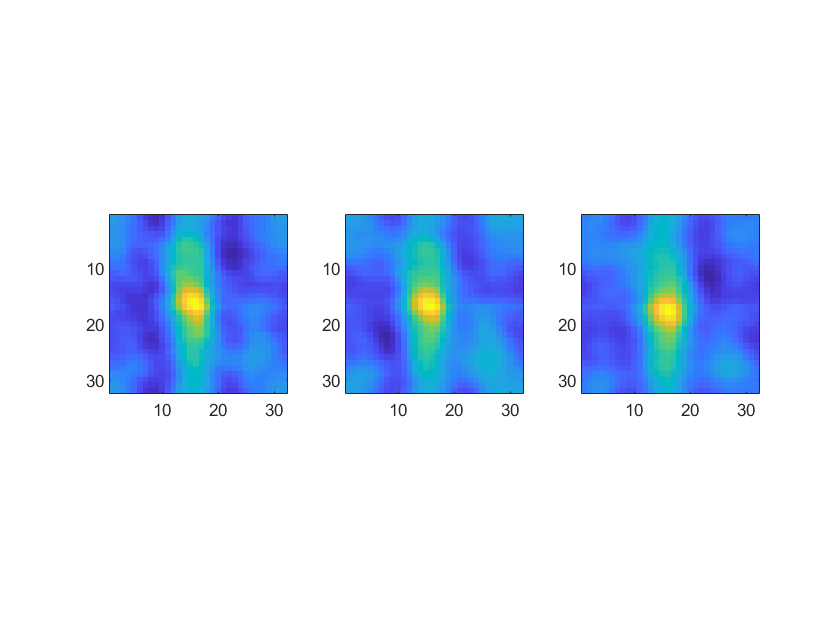

ans = 4

ans = 4

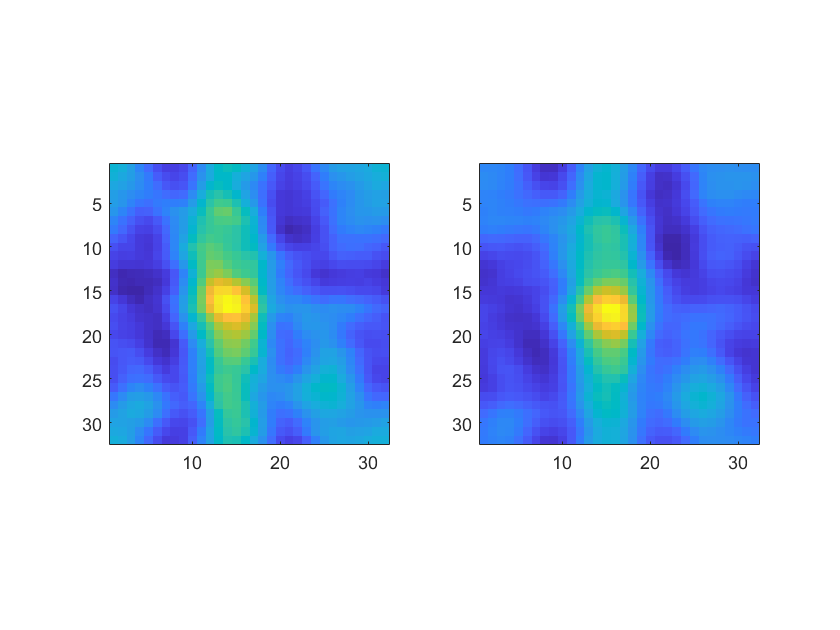

ans = 5

ans = 5

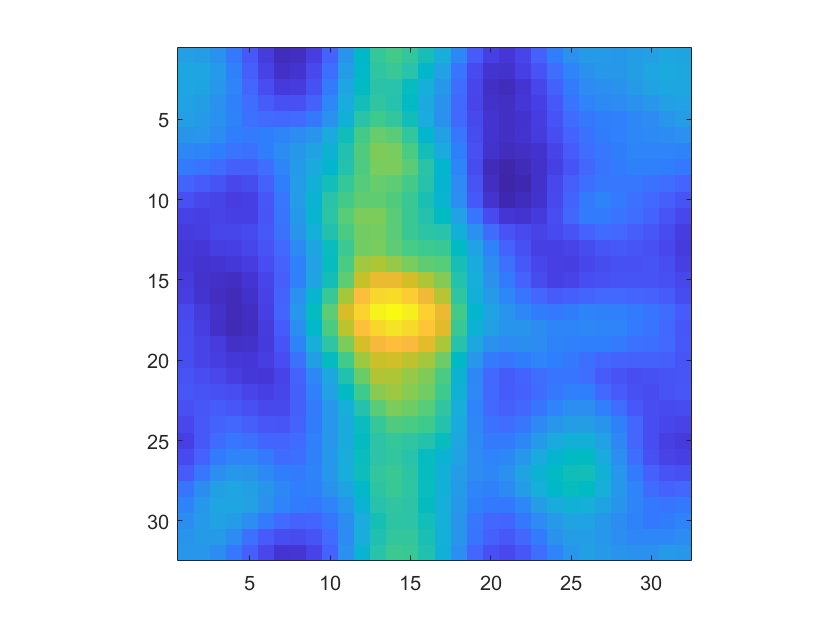

upperTauLimit = min(opt.tauLimit, size(regionanalyse,3));

    fftStack = double(zeros(size(regionanalyse)));
    imageMean = squeeze(mean(mean(regionanalyse,1),2));   
    imageMean(imageMean==0)=10^-12;    
    for frame = 1:size(regionanalyse,3)
        fftStack(:,:,frame) = fft2(double(regionanalyse(:,:,frame)));
    end
  
    for tau = 0:upperTauLimit-1
        lagcorr = zeros(size(regionanalyse,1),size(regionanalyse,2),(size(regionanalyse,3)-tau));
        for pair=1:(size(regionanalyse,3)-tau)
            %lagcorr(:,:,pair) = fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau)));
            lagcorr(:,:,pair) = ifft2(fftStack(:,:,pair).*conj(fftStack(:,:,(pair+tau))),'symmetric')./(imageMean(pair)*imageMean(pair+tau));
                
        end
        %timecorr(:,:,(tau+1)) = fftshift(ifft2mod(mean(lagcorr,3),'symmetric'));
        timecorr(:,:,(tau+1)) = fftshift(mean(lagcorr,3))./size(regionanalyse,1)./size(regionanalyse,2)-1;
        
        size(timecorr, 3)
        
%         % Checks for significance of global maximum
%         if (tau==(upperTauLimit-1))||(~correlationSignificance(timecorr(:,:,tau+1)))
%             timecorr = timecorr(:,:,1:(end-1)); % cut off the "bad" lag
%             break
%         end

        size(timecorr, 3)

        figure
        for frame = 1:size(lagcorr, 3)
            subplot(1,size(lagcorr, 3),frame);
            imagesc(fftshift(lagcorr(:,:,frame))); axis image;
        end
    end

Regions of interest:

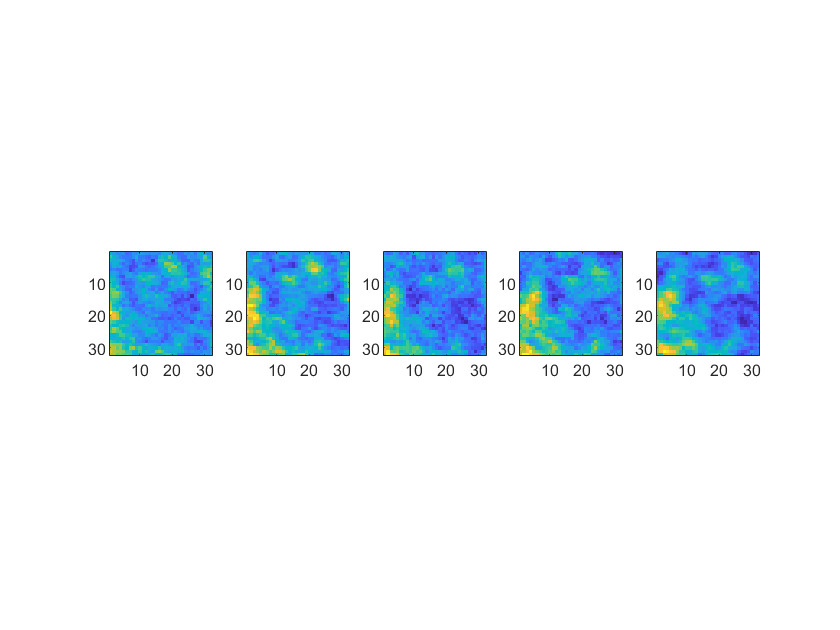

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(regionanalyse(:,:,frame)); axis image;
end

The flow is now much more clearer by simple eye inspection.

Here are the IC(C)S functions:

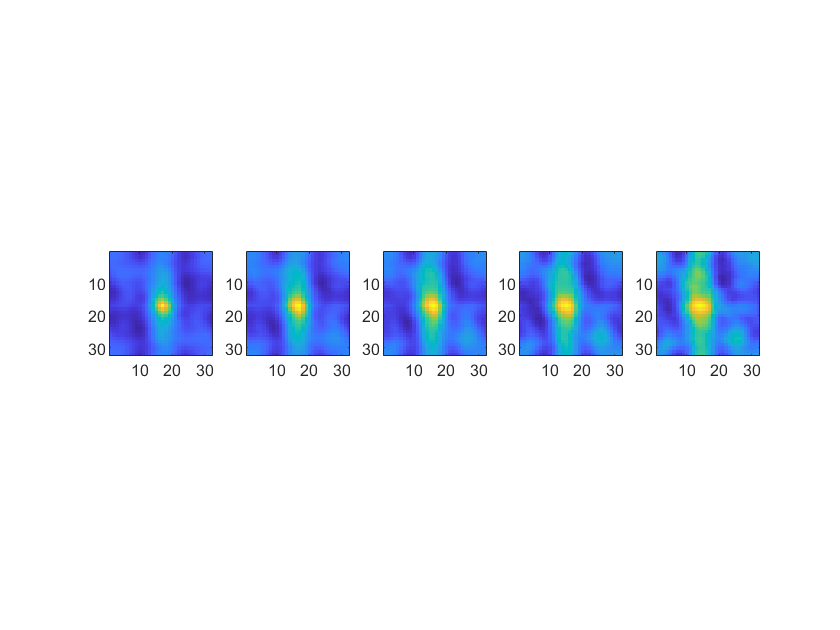

figure
for frame = 1:opt.TOIsize
    subplot(1,opt.TOIsize,frame);
    imagesc(timecorr(:,:,frame)); axis image;
end

Significant ones:

figure
for frame = 1:size(corrfn,3)
    subplot(1,size(corrfn,3),frame);
    imagesc(corrfn(:,:,frame)); axis image; hold on
%     plot(velocityMap{k}.coeffGtime{i,j}(frame,5)/opt.pixelSize+(opt.ROIsize/2)+1,...
%         velocityMap{k}.coeffGtime{i,j}(frame,6)/opt.pixelSize+(opt.ROIsize/2)+1, "+r","LineWidth",1.5);
end

velocityMap{k}.coeffGtime{i,j}

ans =     0.0090    0.4666    0.4666   -0.0005    0.0550    0.0550
    0.0083    0.4906    0.4906   -0.0005   -0.0259    0.0623
    0.0077    0.5166    0.5166   -0.0005   -0.1024    0.0488
    0.0064    0.5387    0.5387   -0.0005   -0.1754    0.0448


We are now at a significance ratio of

disp([num2str(size(corrfn,3)/size(timecorr,3)*100), '%']);

100%


In this case, increasing the ROI size had a positive effect on the information available for the determination of the vector velocities. However, if we keep increasing the ROI size, then sure, the flow may be easier to detect, until a certain point after which the flow within the region of interest becomes heterogeneous in magnitude and orientation, at which point increasing the ROi size will simply result in the masking of these local currents, thus missing them. Eventually, if the ROI size is too big, then the flow magnitude is so small with respect to the whole field of view, that it will not be detected. 

## TOI size effect

Something similar happens with the TOI size. One must keep in mind that it is a linear regression the one being applied to the peak center coordinates, so the assumption is that during a given period of time, the flow can be approximated as being linear. For this reason, the size of the TOI must be small enough to keep the flow within a linear regime: any changes in time of the flow orientation or speed will end up getting masked inside a poorly fitted linear model if the TOI is too big. On the other side, if the TOI is too small, then the number of points available may not be sufficient to obtain an optimal fitting. In theory, if all of the IC(C)S funcions are significant, then more information can be potentially obtained by incresing the TOI size, provided that the ROI size has been adjusted appropriatedly. The posibility of hiding a non-linear flow inside a linear fit must always be kept in mind though.

Let's follow the previous procedure to see the effect of the ROI size and the TOi size on the same vector but this time using a TOI of 10 frames. The first row is the data of the region of interest, the second row are all the correlation functions and the third row shows only the significant ones:

### 210108-2-3-MYL9-ROI6 ROI size = 8x8, TOI size = 10, SR = 10%

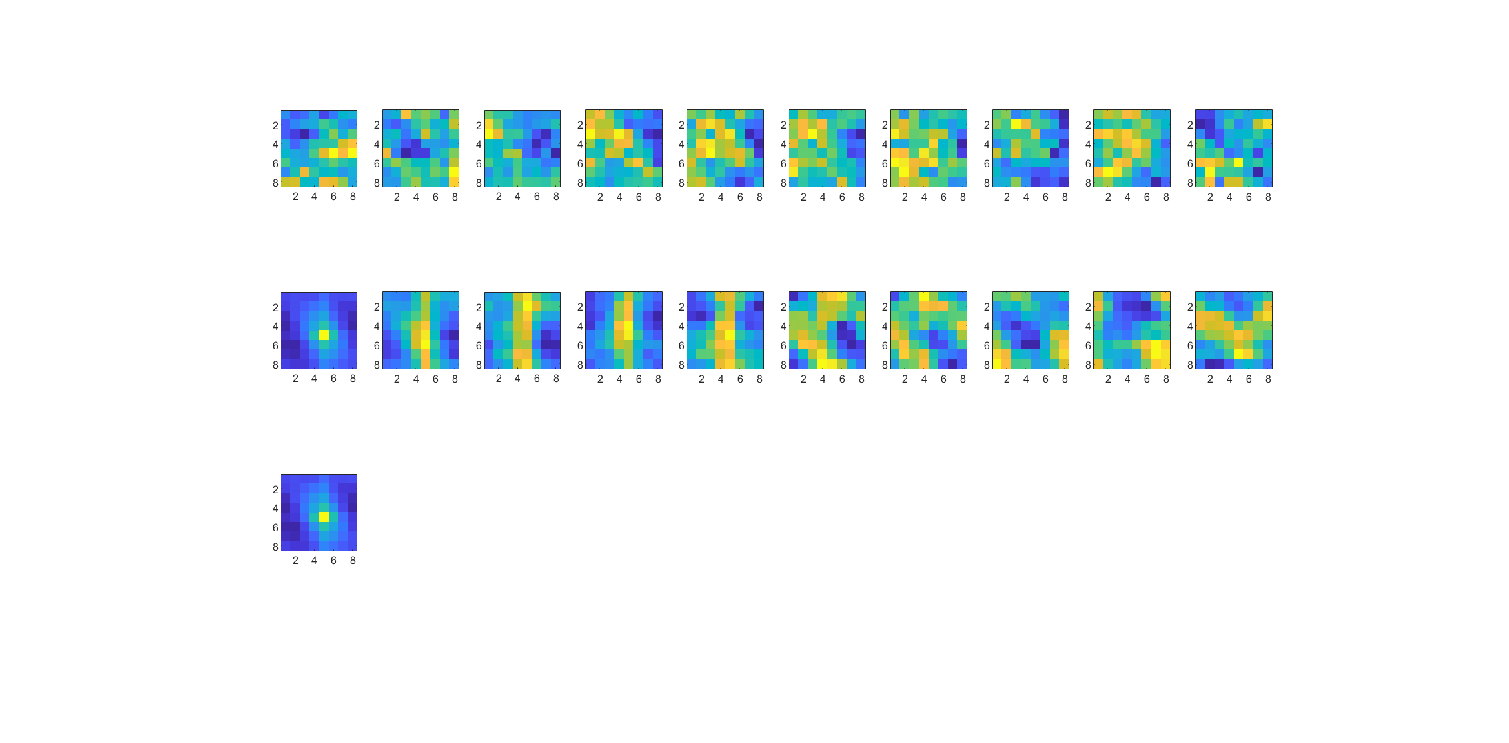

figure; imshow('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\210108-2-3-MYL9_reg_205px-ROI6_8x4_10x1_t100r8o8v5_CorrPanel.png');

### 210108-2-3-MYL9-ROI6 ROI size = 16x16, TOI size = 10, SR = 80%

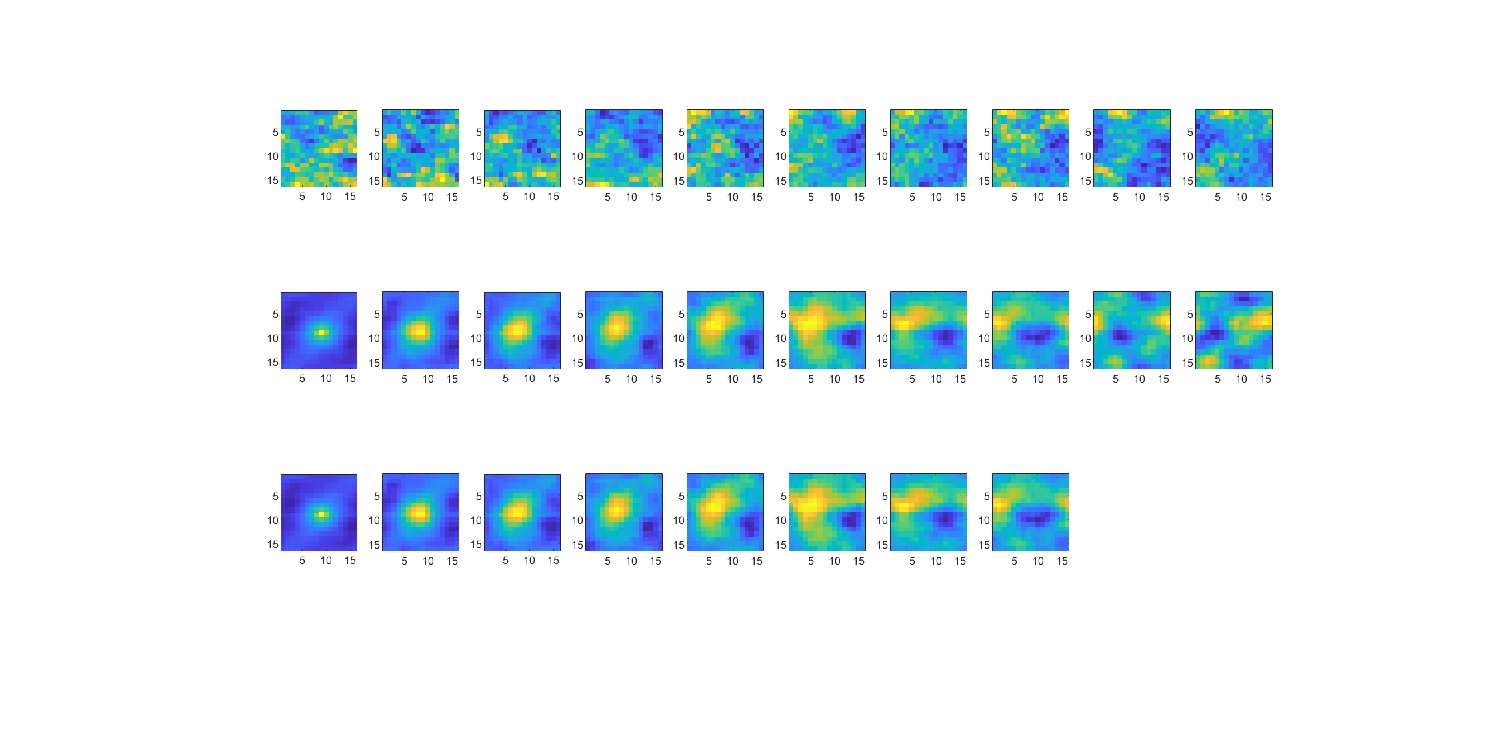

figure; imshow('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\210108-2-3-MYL9_reg_205px-ROI6_16x4_10x1_t100r16o16v5_CorrPanel.png');

### 210108-2-3-MYL9-ROI6 ROI size = 32x32, TOI size = 10, SR = 70%

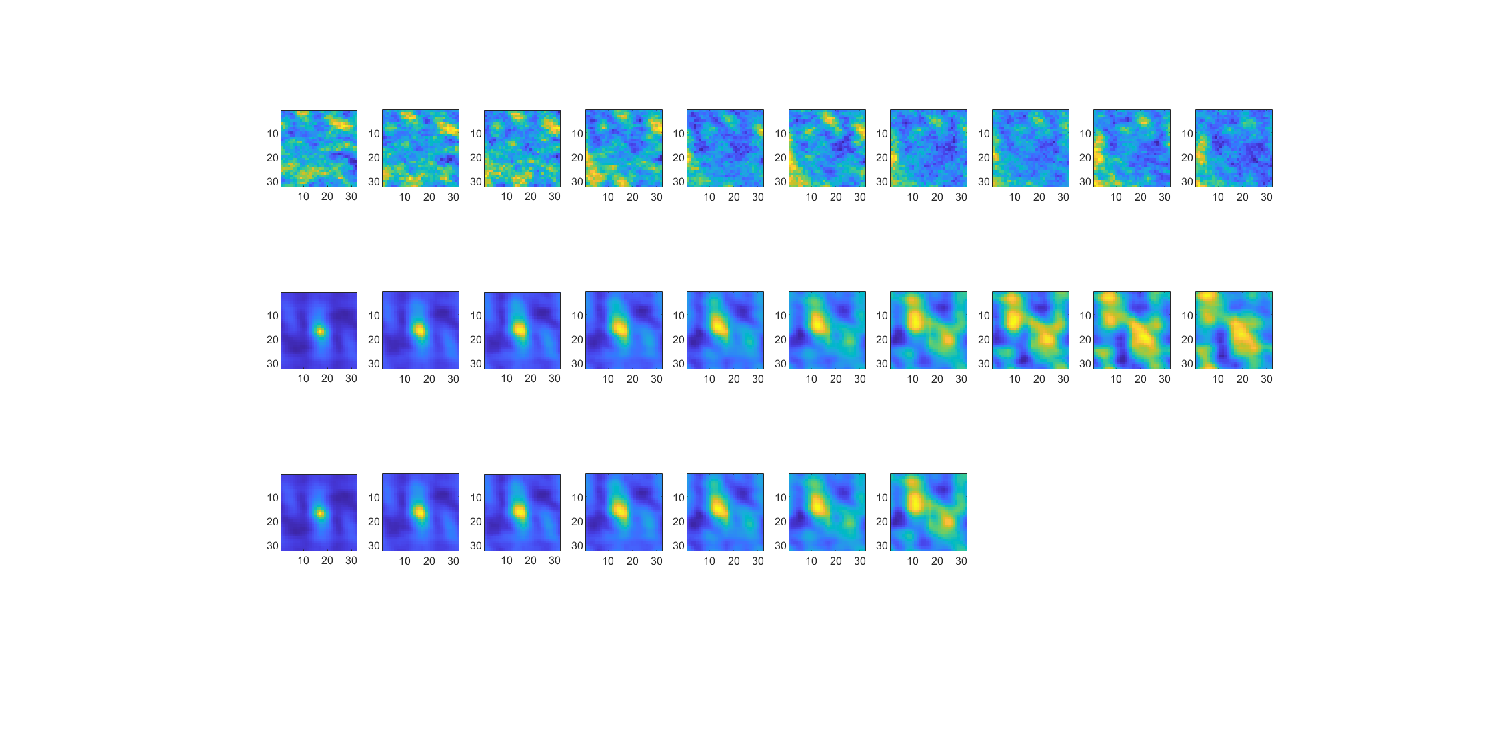

figure; imshow('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\210108-2-3-MYL9_reg_205px-ROI6_32x4_10x1_t100r32o32v5_CorrPanel.png');

As you can see, in this example, using a ROI of 16x16 yielded a better SR than using a ROi of 32x32 pixels. Also, in these two ROI settings, we were able to go beyond 5 significant correlation functions, so it was worth it to extend our TOI to 10. 

## Whole vector map SR estimation

However, we need to keep in mind that all of this has been to determine the velocity magnitude and direction of a single vector, and that the SR will change from one region to another, even when using the same parameter combination. To be able to better estimate what parameter combination works best not only for a single vector but for the whole vector field, I have included the SR calculation inside the `stics_vectormapping.m` function so that each frame of the velocity map stack can be seen as a map or the SR.

Here you will see the SR of the whole vector map for this frame for different conditions. The rows indicate the TOI size from 5, 10, and 20 frames while the columns indicate the ROI size from 8 to 16 to 32 pixels$^2$. All color maps are scaled to `[0,1]`.

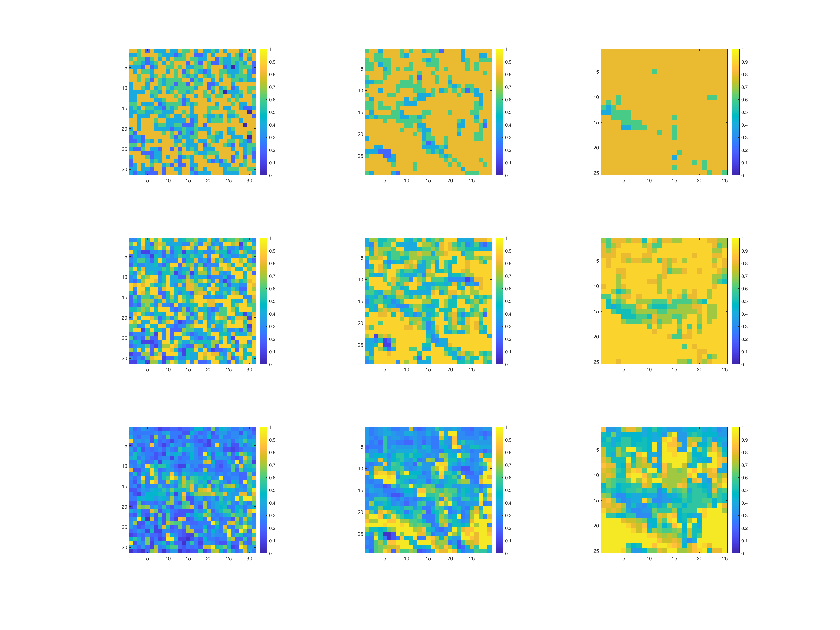

figure;counter = 1;
for toisize = [5,10,20]
    for roisize = [8,16,32]
         subplot(3,3,counter);
         title('Test');
         imshow(['C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\',...
             'VelocityMap210108-2-3-MYL9_reg_205px-ROI6_',num2str(roisize),'x4_',num2str(toisize),...
             'x1_t100r',num2str(roisize),'o',num2str(roisize),'v5_sigK2Map.png']);
         counter = counter+1;
    end
end

As you can see it seems that a ROI size of 32 (third column) and a TOI size of 5 frames  (first row) would have the best results here. The combination of a ROI size of 32x32 and a TOi of 10 also looks priomising but with more spatial heterogeneity. 

## Optimal values of SR

At first glance, one would think that having a SR of 100% would be the best case scenario. However, if this is the case, it can indicate that the velocity determination could have potentially benefited from a frame or two more to get more data. In that sense, the best SR ratio would be slightly underneath the 100%.

## SR depth

Another thing to notice is that as the TOI size increases, the number of possible correlation function increases, which results in a larger set of possible values for SR. For instance when TOI = 5, SR can be {0.2,0.4,0.6,0.8,1} but when TOI = 10, then SR = {0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1}. This results in SR maps with increasing "bit depth" or "SR depth". The optimal SR value would be one minus the SR depth: almost perfect is best!

## Temporal average SR maps

Since these SR maps can be built for each frame of the resulting vector maps stack, and since the parameter combination may not necessarily be optimal for all the TOIs, we can instead calculate the SR mean maps:

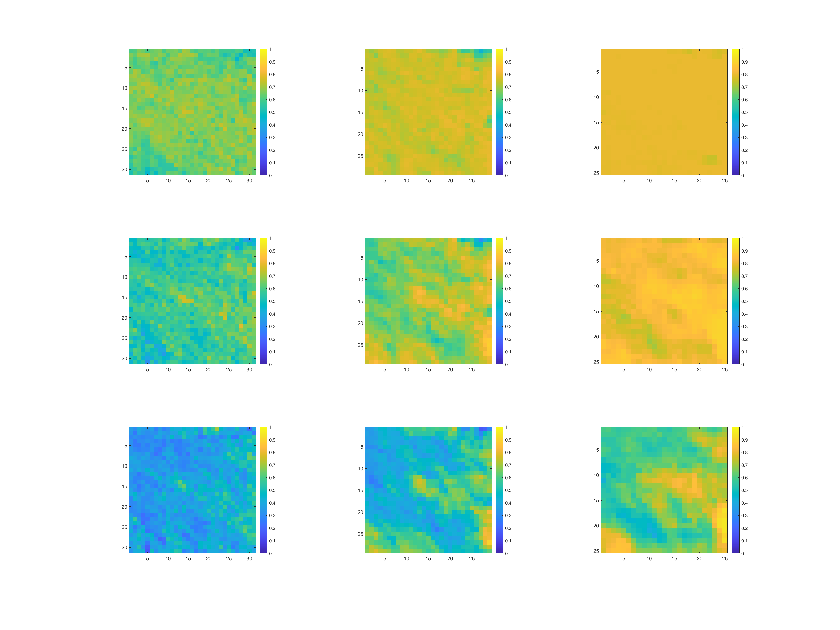

figure;counter = 1;
for toisize = [5,10,20]
    for roisize = [8,16,32]
         subplot(3,3,counter);
         title('Test');
         imshow(['C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\',...
             'VelocityMap210108-2-3-MYL9_reg_205px-ROI6_',num2str(roisize),'x4_',num2str(toisize),...
             'x1_t100r',num2str(roisize),'o',num2str(roisize),'v5_sigMeanMap.png']);
         counter = counter+1;
    end
end

This looks a lot better. However, in the spirit of breaking the ties between TOI 5 and TOI 10, we can focus on the minimal values of the SR maps:

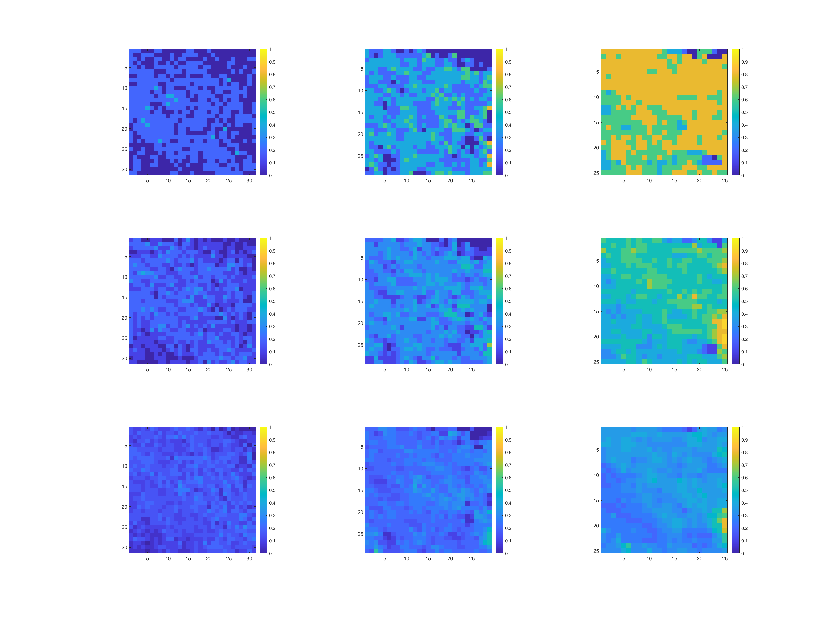

figure;counter = 1;
for toisize = [5,10,20]
    for roisize = [8,16,32]
         subplot(3,3,counter);
         title('Test');
         imshow(['C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\',...
             'VelocityMap210108-2-3-MYL9_reg_205px-ROI6_',num2str(roisize),'x4_',num2str(toisize),...
             'x1_t100r',num2str(roisize),'o',num2str(roisize),'v5_sigMinMap.png']);
         counter = counter+1;
    end
end

And we have a winner! We now know that the best parameter combination for this dataset would be ROI = 32x32, TOI = 5. 

To be able to guide the parameter selection, we don't need to do all of this though. We can base ourselves in a few vector fields to estimate this. I could show that as we increase the number of vector field frames, the winning condition emerges pretty quickly. Since each TOI can take minutes to compute, it would be affordable to wait a couple of minutes to get estimates of the best parameter combinations to explore. 

Furthermore, since the parameter selection allows us to select spatiotemporal regimes, this could be used to pick up selected features in the image.

                [coeffGtime] = gaussfit(corrfn,'time',opt.pixelSize,'n',opt.fitRadius); coeffGtime(:,5:6)

ans =     0.0550    0.0550
    0.0204    0.0255
   -0.0010    0.0172
   -0.0194   -0.0013
    0.0082   -0.0618


                [coeffGrotated] = gaussfit(corrfn,'rotated',opt.pixelSize,'n',opt.fitRadius); coeffGrotated(:,5:6)

ans =     0.0550    0.0551
    0.0212    0.0228
    0.0033    0.0148
   -0.0128    0.0006
    0.0195   -0.0542


                [Px, Sx] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))', 1); Px

Px =    -0.0040    0.1354


                [Py, Sy] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),6))', 1); Py

Py =    -0.0000    0.0562


                
                [PxR, SxR] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGrotated(1:size(corrfn,3),5))', 1);
                [PyR, SyR] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGrotated(1:size(corrfn,3),6))', 1);                
                
%                 velocityMap{k}.Px(u,2:-1:1) = Px;
%                 velocityMap{k}.Py(u,2:-1:1) = Py;
%                 velocityMap{k}.Sx(u) = Sx;
%                 velocityMap{k}.Sy(u) = Sy;
                [Ex, deltax] = polyval(Px, opt.timeFrame*(1:size(corrfn,3)), Sx)

Ex =     0.0558   -0.0238   -0.1034   -0.1830   -0.2626


deltax =     0.0072    0.0065    0.0062    0.0065    0.0072


                xresid = squeeze(coeffGtime(1:size(corrfn,3),5))' - Ex; 
                SSxresid = sum(xresid.^2); 
                SSxtotal = (length(squeeze(coeffGtime(1:size(corrfn,3),5))')-1 * var(squeeze(coeffGtime(1:size(corrfn,3),5))'));
                xrsq = 1 - SSxresid/SSxtotal

xrsq = 1.0000

                SSxresid/SSxtotal

ans = 1.9319e-05

                [Ey, deltay] = polyval(Py, opt.timeFrame*(1:size(corrfn,3)), Sy)

Ey =     0.0556    0.0549    0.0543    0.0536    0.0530


deltay =     0.0109    0.0098    0.0094    0.0098    0.0109


                yresid = squeeze(coeffGtime(1:size(corrfn,3),6))' - Ey; 
                SSyresid = sum(yresid.^2); 
                SSytotal = (length(squeeze(coeffGtime(1:size(corrfn,3),6))')-1 * var(squeeze(coeffGtime(1:size(corrfn,3),6))'));
                yrsq = 1 - SSyresid/SSytotal

yrsq = 1.0000

                SSyresid/SSytotal

ans = 4.4293e-05

                
                [ExR, deltaxR] = polyval(PxR, opt.timeFrame*(1:size(corrfn,3)), SxR)

ExR =     0.0576   -0.0281   -0.1137   -0.1994   -0.2850


deltaxR =     0.0034    0.0031    0.0029    0.0031    0.0034


                xRresid = squeeze(coeffGrotated(1:size(corrfn,3),5))' - ExR; 
                SSxRresid = sum(xRresid.^2); 
                SSxRtotal = (length(squeeze(coeffGrotated(1:size(corrfn,3),5))')-1 * var(squeeze(coeffGrotated(1:size(corrfn,3),5))'));
                xRrsq = 1 - SSxRresid/SSxRtotal

xRrsq = 1.0000

                SSxRresid/SSxRtotal                

ans = 4.3653e-06

                [EyR, deltayR] = polyval(PyR, opt.timeFrame*(1:size(corrfn,3)), SyR)

EyR =     0.0600    0.0489    0.0378    0.0267    0.0155


deltayR =     0.0075    0.0067    0.0065    0.0067    0.0075


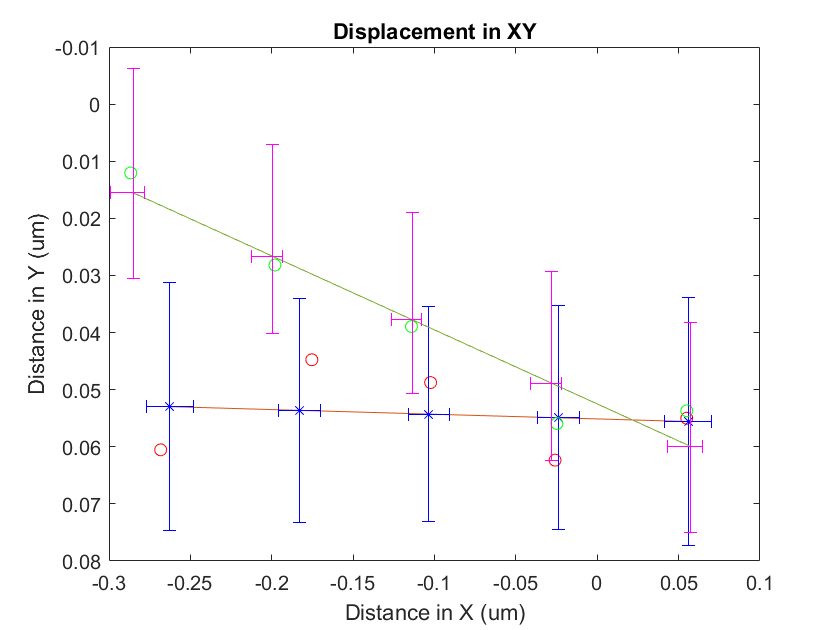

figure;
plot(coeffGtime(:,5), coeffGtime(:,6), "or"); hold on
plot([Ex(1), Ex(end)], [Ey(1), Ey(end)]);
xpos = 2.*deltax; xneg = xpos;
ypos = 2.*deltay; yneg = ypos;
errorbar(Ex, Ey, yneg, ypos, xneg, xpos, "*b")

plot(coeffGrotated(:,5), coeffGrotated(:,6), "og");
plot([ExR(1), ExR(end)], [EyR(1), EyR(end)]);
xposR = 2.*deltaxR; xnegR = xpos;
yposR = 2.*deltayR; ynegR = ypos;
errorbar(ExR, EyR, ynegR, yposR, xnegR, xposR, "+m")

title('Displacement in XY'); 
xlabel('Distance in X (um)'); ylabel('Distance in Y (um)');
% xlim([-opt.pixelSize*opt.ROIsize/16, opt.pixelSize*opt.ROIsize/16]); 
% ylim([-opt.pixelSize*opt.ROIsize/16, opt.pixelSize*opt.ROIsize/16]);
axis ij; hold off;

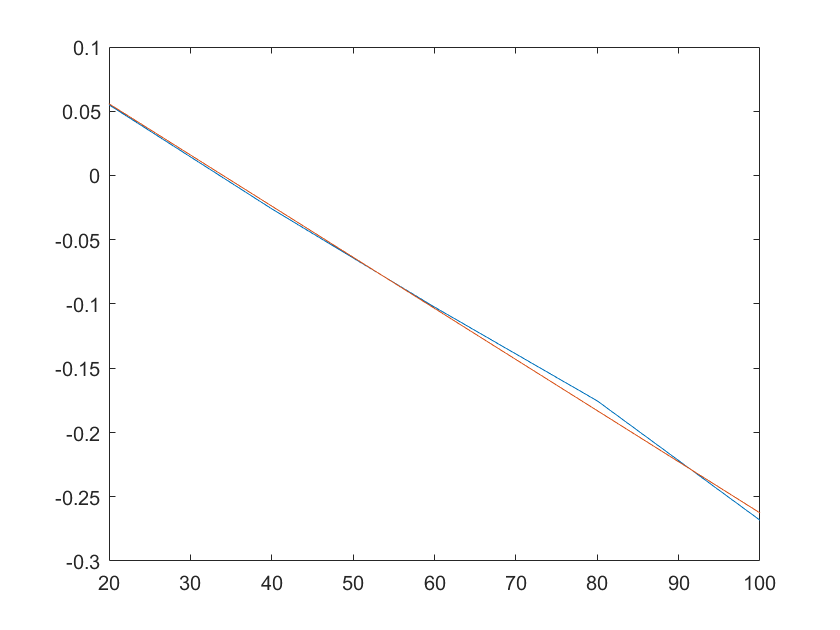

% [Px, Sx] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))', 1); Px
plot(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))'); hold on;
xlim = [-10, max(opt.timeFrame*(1:size(corrfn,3)))];
plot(opt.timeFrame*(1:size(corrfn,3)), polyval(Px, opt.timeFrame*(1:size(corrfn,3))));hold off

velocityMap{k}.Px(i,j)

ans = 0.1297

velocityMap{k}.vx(i,j)

ans = -0.0038

velocityMap{k}.vy(i,j)

ans = -2.2154e-04

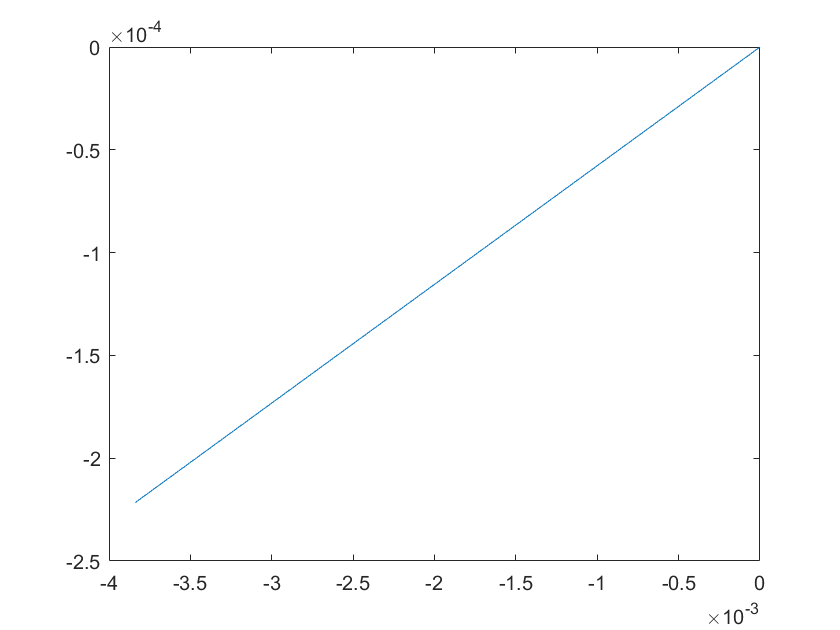

plot([0, velocityMap{k}.vx(i,j)], [0, velocityMap{k}.vy(i,j)]);

theta = atand(velocityMap{k}.vy(i,j)/velocityMap{k}.vx(i,j))

theta = 3.3035

if velocityMap{k}.vx(i,j)>0 && velocityMap{k}.vy(i,j)>0
    omega = theta
elseif velocityMap{k}.vx(i,j)<0 && velocityMap{k}.vy(i,j)>0
    omega = 180-(-theta)
elseif velocityMap{k}.vx(i,j)>0 && velocityMap{k}.vy(i,j)<0
    omega = 360 - theta
elseif velocityMap{k}.vx(i,j)<0 && velocityMap{k}.vy(i,j)<0
    omega = 180 + theta
end

omega = 183.3035

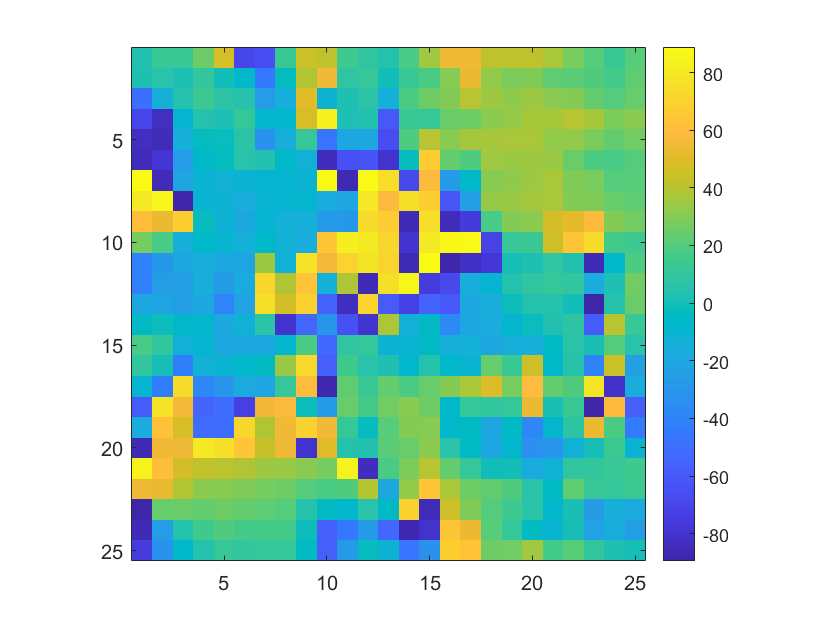

theta = atand(velocityMap{k}.vy./velocityMap{k}.vx); imagesc(theta); colorbar; axis image

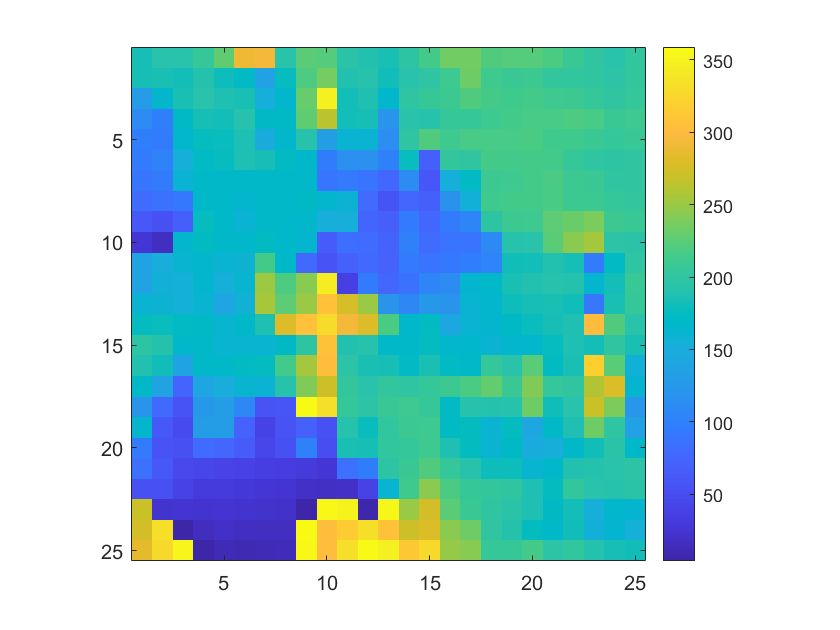

theta = atand(velocityMap{k}.vy./velocityMap{k}.vx);
omega = zeros(size(velocityMap{k}.vx,1), size(velocityMap{k}.vy,2));
w=1;
for i = 1:size(velocityMap{k}.vx,1)
    for j = 1:size(velocityMap{k}.vx,2)
        if velocityMap{k}.vx(i,j)>0 && velocityMap{k}.vy(i,j)>0
            omega(i,j) = theta(i,j);
        elseif velocityMap{k}.vx(i,j)<0 && velocityMap{k}.vy(i,j)>0
            omega(i,j) = 180 - (-theta(i,j));
        elseif velocityMap{k}.vx(i,j)>0 && velocityMap{k}.vy(i,j)<0
            omega(i,j) = 360 - (-theta(i,j));
        elseif velocityMap{k}.vx(i,j)<0 && velocityMap{k}.vy(i,j)<0
            omega(i,j) = 180 + theta(i,j);
        end
    end
end
imagesc(omega); colorbar; axis image

Load Data Stack

[fileID, filePath] = uigetfile("*.tif");
stack = readFileToStack([filePath, fileID]);

Load Vector Field if available:

[VMfile, VMpath] = uigetfile("*.mat");
load([VMpath, VMfile]);

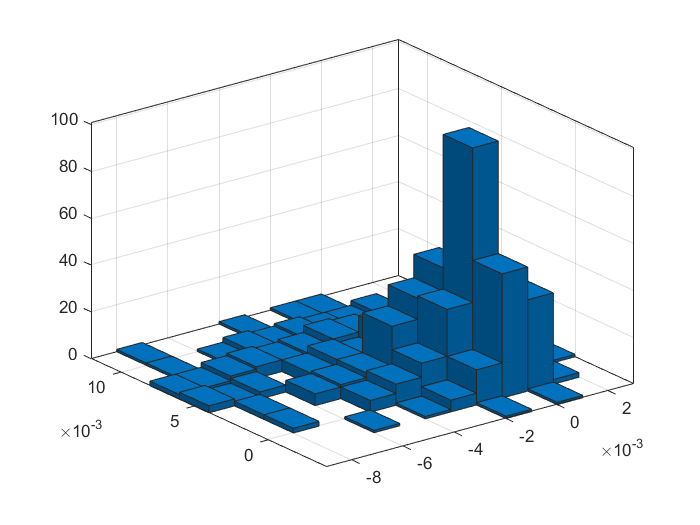

frame = 3;
if mod(opt.TOIsize, 2) ==  0 % TOI size is even
    minK = 1;
else
    minK = 0;
end
k = frame - floor(opt.TOIsize/2) + minK; % Vector field frame
figure;
histogram2(velocityMap{k}.Px(:,2),velocityMap{k}.Py(:,2)); 

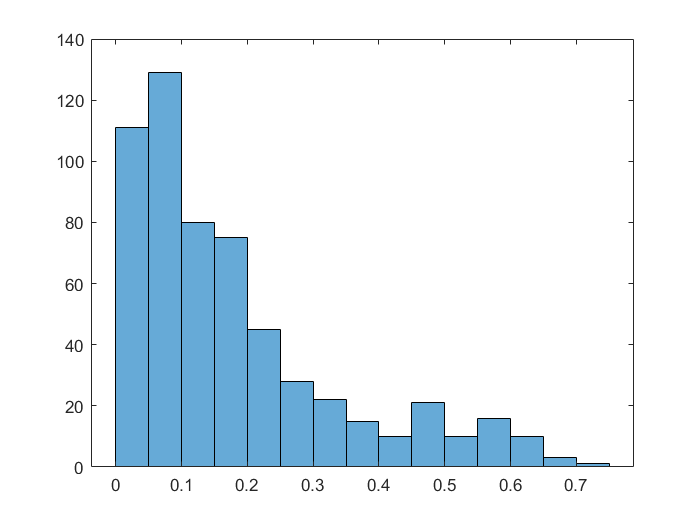

figure;
histogram(velocityMap{k}.VelMap);

figure; 
for k = 1:length(velocityMap)
    ksdensity(velocityMap{k}.VelMap); hold on;
end

[fileList, filePath] = uigetfile(".mat","MultiSelect","on");
if ischar(fileList) % Only one file selected
    fileList = {fileList};
end


statistics(length(fileList)) = struct;
labels = cell(1,length(fileList));

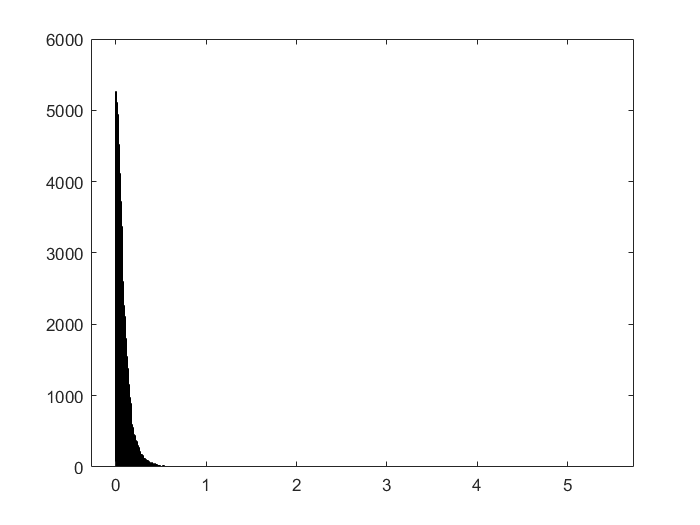

<0.25: 52597/55296 = 0.95119


<0.5: 54936/55296 = 0.99349


<1: 55153/55296 = 0.99741



figure;
for fileIx = 1:length(fileList)
    load([filePath, fileList{fileIx}]); 
    fileName = fileList{fileIx}; fileName = fileName(1:end-4);
    
    stack = readFileToStack(opt.filePath{1,1});
    
    fracROIshift = opt.ROIsize/opt.ROIshift;
    fracTOIshift = opt.TOIsize/opt.TOIshift;

    along_y = floor((size(stack,2)-opt.ROIsize)/opt.ROIshift)+1;
    along_x = floor((size(stack,1)-opt.ROIsize)/opt.ROIshift)+1;
    along_t = floor((size(stack,3)-opt.TOIsize)/opt.TOIshift)+1;

%     for k=1:along_t
%         velocityMap{k}.VelMap = zeros(along_x, along_y);
%         velocityMap{k}.VelMap = sqrt(velocityMap{k}.vx.^2 + velocityMap{k}.vy.^2).*60;% Convert um/sec to um/min
%     end

    g = 0; % Number of velocity maps with missing vectors
    AllVelMap = zeros(along_x*along_y, length(velocityMap));
    for k = 1:length(velocityMap)    
        tempMap = reshape(velocityMap{k}.VelMap, along_x*along_y, 1);
        AllVelMap(:,k) = tempMap;
%         else
%             AllVelMap(1:size(velocityMap{k}.VelMap, 1),k) = velocityMap{k}.VelMap(:,1);
%             AllVelMap(size(velocityMap{k}.VelMap:size(velocityMap{1}.Px, 1), 1),k) = 0;
%             g = g+1; c(g,1) = k; c(g,2) = size(velocityMap{k}.VelMap, 1);
%         end
    end


%     [f, xi] = ksdensity(VecAllVelMap); 
%     plot(xi,f/900); hold on;
    figure;
    h = histogram(AllVelMap);
    h.FaceAlpha = 0.2;
    labels{1, fileIx} = ['ROI size = ', num2str(opt.ROIsize)];
    statistics(fileIx).N = size(AllVelMap, 1)*size(AllVelMap, 2);
    statistics(fileIx).nZeros = sum(AllVelMap(:,:)<= 0.001,"all");
    disp(['<0.25: ',num2str(sum(AllVelMap(:,:)<= 0.25,"all")),'/',num2str(statistics(fileIx).N),' = ',num2str(sum(AllVelMap(:,:)<= 0.25,"all")/statistics(fileIx).N)]);
    disp(['<0.5: ',num2str(sum(AllVelMap(:,:)<= 0.5,"all")),'/',num2str(statistics(fileIx).N),' = ',num2str(sum(AllVelMap(:,:)<= 0.5,"all")/statistics(fileIx).N)]);
    disp(['<1: ',num2str(sum(AllVelMap(:,:)<= 1,"all")),'/',num2str(statistics(fileIx).N),' = ',num2str(sum(AllVelMap(:,:)<= 1,"all")/statistics(fileIx).N)]);
    statistics(fileIx).Mean = mean(AllVelMap,"all","omitnan");
    statistics(fileIx).Median = median(AllVelMap,"all","omitnan");
%     statistics(fileIx).Mode = mode(AllVelMap,"all");
    statistics(fileIx).Min = min(AllVelMap,[],"all");
    statistics(fileIx).Max = max(AllVelMap,[],"all");
    statistics(fileIx).Std = std(AllVelMap,[],"all","omitnan");
    statistics(fileIx).Skewness = skewness(AllVelMap);
    statistics(fileIx).Kurtosis = kurtosis(AllVelMap);

end

% legend(labels);
% xlim([-0.1, 2]); ylim([0 1.8]);

prctile(AllVelMap, 0, "all")

ans = 1.6164e-18

prctile(AllVelMap, 99)

ans =     0.6364    0.7049    0.5384    0.4699    0.3774    0.3743    0.3290    0.2934    0.3187    0.2878    0.2601    0.3114    0.3794    0.4160    0.4567    0.9576    0.9805    0.5194    0.3711    1.1809    0.6170    0.2971    1.6548    0.3506    0.2455    0.1678    1.6169    0.2400    2.5738    2.8696    0.2864    0.2140    0.1655    0.1940    0.1939    0.1805    0.1985    0.1733    0.1331    0.1459    0.1249    0.1788    0.2063    0.1920    0.1818    0.1409    0.1880    0.1469    0.1917    0.1749


[v,idx] = max(prctile(AllVelMap, 99))

v = 2.8696

idx = 30

prctile(AllVelMap, 99, "all")

ans = 0.4317

round(prctile(AllVelMap, 99, "all"),2)

ans = 0.4300

statistics

statistics = struct with fields:
           N: 55296
      nZeros: 2380
        Mean: 0.0893
      Median: 0.0599
         Min: 1.6164e-18
         Max: 5.4542
         Std: 0.1554
    Skewness: [1×96 double]
    Kurtosis: [1×96 double]


load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-SignificanceContainer.mat');
for i = 1:3:12
    ['ROI = ', num2str(sigContainer{i,1}),...
    ', STD = ', num2str(std(sigContainer{i, 7},[], 'all')),...
    ', Median = ', num2str(median(sigContainer{i,7}, 'all'))]
end

ans = 'ROI = 8, STD = 0.18094, Median = 0.66667'

ans = 'ROI = 16, STD = 0.13979, Median = 0.66667'

ans = 'ROI = 32, STD = 0.06898, Median = 0.66667'

ans = 'ROI = 64, STD = 0.036933, Median = 0.66667'

figure;
% VecAllVelMap = reshape(AllVelMap,[size(AllVelMap,1)*size(AllVelMap,2),1]);
% VecAllVelMap = VecAllVelMap.*60; % Convert um/hr to um/min
[f, xi] = ksdensity(AllVelMap); 

Error using ksdensity (line 212)
X must be a non-empty vector or two-column matrix.

plot(xi,f);
title('Absolute Velocity Distributions');
ylabel('Probability distribution function (PDF)');
xlabel('Velocity vector magnitude (\mum /min)');

% histogram(VecAllVelMap);